clear; clc; close all;
% Script written by Jo Wayne Tan, jwt617, to produce plots for PEQUOD
% manual

width = 2; % Line thickness
lsize = 12.5; tsize = 14; legsize = 11; msize = 10; % Font size in label, title, legend, markers
tickersize = 15;
set(0, 'defaultAxesTickLabelInterpreter', 'latex');
set(0, 'defaultTextInterpreter', 'latex'); set(0, 'defaultLegendInterpreter', 'latex');

% Colours - Matlab defaults
blue = [0 0.4470 0.7410]; orange = [0.8500 0.3250 0.0980]; yellow = [0.9290 0.6940 0.1250];
purple = [0.4940 0.1840 0.5560]; green = [0.4660 0.6740 0.1880]; 
lblue = [0.3010 0.7450 0.9330];	red = [0.6350 0.0780 0.1840]; black = [0 0 0];

## Grid

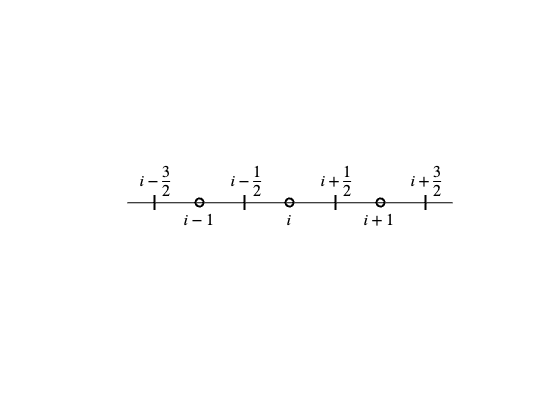

figure
hold on; grid off; box off
set(gca,'visible','off')
plot(0.25, 0, 'o', 'LineWidth', width, 'MarkerSize', msize - 2, 'Color', black)
plot(0.50, 0, 'o', 'LineWidth', width, 'MarkerSize', msize - 2, 'Color', black)
plot(0.75, 0, 'o', 'LineWidth', width, 'MarkerSize', msize - 2, 'Color', black)
plot(0.125, 0, '|', 'LineWidth', width, 'MarkerSize', msize + 5, 'Color', black)
plot(0.375, 0, '|', 'LineWidth', width, 'MarkerSize', msize + 5, 'Color', black)
plot(0.625, 0, '|', 'LineWidth', width, 'MarkerSize', msize + 5, 'Color', black)
plot(0.875, 0, '|', 'LineWidth', width, 'MarkerSize', msize + 5, 'Color', black)
text(0.485, -0.01, '$i$', 'FontSize', lsize + 3.5, 'Interpreter', "latex")
text(0.2, -0.01, '$i-1$', 'FontSize', lsize + 3.5, 'Interpreter', "latex")
text(0.7, -0.01, '$i+1$', 'FontSize', lsize + 3.5, 'Interpreter', "latex")
text(0.08, 0.0125, '$i-\frac{3}{2}$', 'FontSize', lsize + 3.5, 'Interpreter', "latex")
text(0.33, 0.0125, '$i-\frac{1}{2}$', 'FontSize', lsize + 3.5, 'Interpreter', "latex")
text(0.58, 0.0125, '$i+\frac{1}{2}$', 'FontSize', lsize + 3.5, 'Interpreter', "latex")
text(0.83, 0.0125, '$i+\frac{3}{2}$', 'FontSize', lsize + 3.5, 'Interpreter', "latex")
plot([0.05 0.95], [0 0], 'color', black, 'LineWidth', width - 1)
xlim([-0.1 1.1]), ylim([-0.1 0.1]);
hold off


ax = gca;

## N-layered oceans

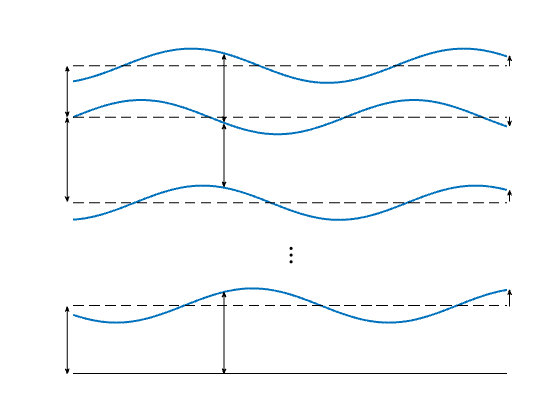

x = linspace(0, 1, 100);
amp = 0.05;
freq = 10;
level1 = 0.9;
level2 = 0.75;
level4 = 0.2;
level3 = 0.5;

wave1 = amp * sin(freq * (x - 2.)) + level1;
wave2 = amp * sin(freq * (x - 0.)) + level2;
wave3 = amp * sin(freq * (x + 3.)) + level3;
wave4 = amp * sin(freq * (x + 1.)) + level4;
ahs = 5;

figure
hold on; % grid off; box off
set(gca,'visible','off')
plot(x, wave1, '-', 'LineWidth', width, 'Color', blue)
plot(x, wave2, '-', 'LineWidth', width, 'Color', blue)
plot(x, wave3, '-', 'LineWidth', width, 'Color', blue)
plot(x, wave4, '-', 'LineWidth', width, 'Color', blue)

plot(x, level1 * ones(100), '--', 'LineWidth', width - 1, 'Color', black)
plot(x, level2 * ones(100), '--', 'LineWidth', width - 1, 'Color', black)
plot(x, level3 * ones(100), '--', 'LineWidth', width - 1, 'Color', black)
plot(x, level4 * ones(100), '--', 'LineWidth', width - 1, 'Color', black)
text(0.485, 0.35, '$\vdots$', 'FontSize', lsize + 10, 'Interpreter', "latex")
annotation('doublearrow', [0.12 0.12], [0.11 0.27], "Head1Length", ahs, "Head2Length", ahs, "Head1Width", ahs, "Head2Width", ahs);
annotation('doublearrow', [0.12 0.12], [0.52 0.72], "Head1Length", ahs, "Head2Length", ahs, "Head1Width", ahs, "Head2Width", ahs);
annotation('doublearrow', [0.12 0.12], [0.722 0.842], "Head1Length", ahs, "Head2Length", ahs, "Head1Width", ahs, "Head2Width", ahs);

annotation('doublearrow', [0.4 0.4], [0.11 0.305], "Head1Length", ahs, "Head2Length", ahs, "Head1Width", ahs, "Head2Width", ahs);
annotation('doublearrow', [0.4 0.4], [0.555 0.705], "Head1Length", ahs, "Head2Length", ahs, "Head1Width", ahs, "Head2Width", ahs);
annotation('doublearrow', [0.4 0.4], [0.71 0.87], "Head1Length", ahs, "Head2Length", ahs, "Head1Width", ahs, "Head2Width", ahs)

annotation('arrow', [0.91 0.91], [0.27 0.31], "HeadLength", ahs, "HeadWidth", ahs);
annotation('arrow', [0.91 0.91], [0.52 0.547], "HeadLength", ahs, "HeadWidth", ahs);
annotation('arrow', [0.91 0.91], [0.722 0.7], "HeadLength", ahs, "HeadWidth", ahs);
annotation('arrow', [0.91 0.91], [0.842 0.867], "HeadLength", ahs, "HeadWidth", ahs);

% text(0.2, -0.01, '$i-1$', 'FontSize', lsize + 3.5, 'Interpreter', "latex")
% text(0.7, -0.01, '$i+1$', 'FontSize', lsize + 3.5, 'Interpreter', "latex")
% text(0.08, 0.0125, '$i-\frac{3}{2}$', 'FontSize', lsize + 3.5, 'Interpreter', "latex")
% text(0.33, 0.0125, '$i-\frac{1}{2}$', 'FontSize', lsize + 3.5, 'Interpreter', "latex")
% text(0.58, 0.0125, '$i+\frac{1}{2}$', 'FontSize', lsize + 3.5, 'Interpreter', "latex")
% text(0.83, 0.0125, '$i+\frac{3}{2}$', 'FontSize', lsize + 3.5, 'Interpreter', "latex")
plot([0. 1.], [0 0], 'color', black, 'LineWidth', width)
xlim([0. 1.]), ylim([0. 1.]);
hold off


ax = gca;
% exportgraphics(ax,'/Users/wayne/Desktop/pequod/manual/figs/nlayerdiagram.png','Resolution',1000);

## Stencil

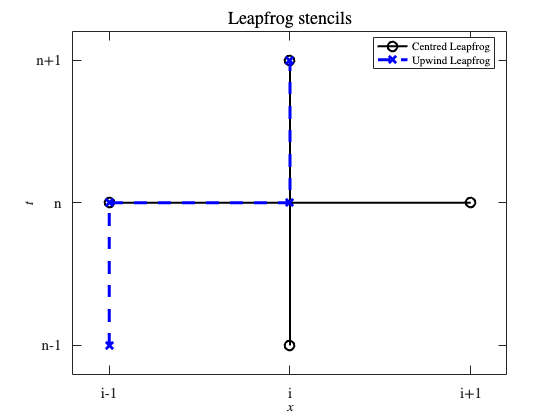

x = [-1 -1 1 1 -1];
y = [-1 1 1 -1 -1];
x2 = [-1 1];
y2 = [0 0];

figure
hold on; box on;
set(gca,'fontsize',tickersize)
plot(x2, y2, 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
plot(y2, x2, 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
plot([0 0], [-1 1], 'o-', 'MarkerSize', msize - 0.5, 'LineWidth', width, 'Color', black);
plot1 = plot([-1 1], [0 0], 'o-', 'MarkerSize', msize - 0.5, 'LineWidth', width, 'Color', black);
plot2 = plot([-1 -1 0 0], [-1 0 0 1], 'x--', 'MarkerSize', msize + 0.5, 'LineWidth', width + 1, 'Color', 'b');
L = legend([plot1 plot2], 'Centred Leapfrog', 'Upwind Leapfrog', 'Location', 'best');
L.FontSize = legsize;
title('Leapfrog stencils', 'FontSize', tsize + 4, 'Interpreter', "latex");
xlim([-1.2 1.2]); ylim([-1.2 1.2]);
ylabel('$t$', 'FontSize', lsize + 2), xlabel('$x$', 'FontSize', lsize + 2);
yticks([-1 0 1]); xticks([-1 0 1]);
yticklabel = {"n-1" "n" "n+1"};
xticklabel = {"i-1" "i" "i+1"};
set(gca, 'XTickLabels', xticklabel, 'TickLabelInterpreter', "latex")
set(gca, 'YTickLabels', yticklabel, 'TickLabelInterpreter', "latex")
hold off


ax = gca;
% exportgraphics(ax,'/Users/wayne/Desktop/NumericsCDT/report/figures/lpstencil.eps','Resolution',300)

## 5-point stencil

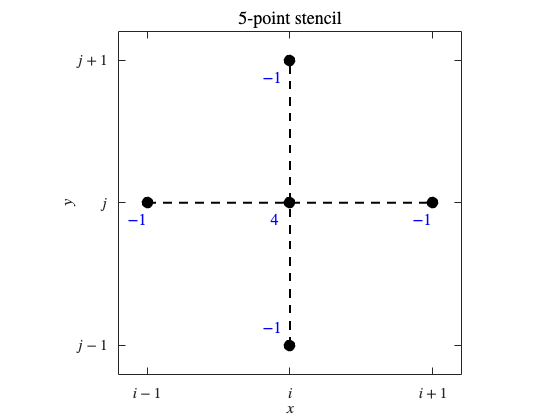

x2 = [-1 1];
y2 = [0 0];

figure
hold on; box on;
axis square;
set(gca,'fontsize',tickersize);
plot(x2, y2, 'LineStyle', '--', 'LineWidth', width, "Color", black);
plot(y2, x2, 'LineStyle', '--', 'LineWidth', width, "Color", black);
plot(y2, y2, 'o', 'MarkerSize', msize - 0.5, 'LineWidth', width, 'MarkerFaceColor', black, 'Color', black);
plot([0 0], [-1 1], 'o', 'MarkerSize', msize - 0.5, 'LineWidth', width, 'MarkerFaceColor', black, 'Color', black);
plot([-1 1], [0 0], 'o', 'MarkerSize', msize - 0.5, 'LineWidth', width, 'MarkerFaceColor', black, 'Color', black);

text(-0.15, -0.12, '$4$', 'FontSize', lsize + 3, 'Color', 'b', 'Interpreter', "latex");
text(-1.15, -0.12, '$-1$', 'FontSize', lsize + 3, 'Color', 'b', 'Interpreter', "latex");
text(0.85, -0.12, '$-1$', 'FontSize', lsize + 3, 'Color', 'b', 'Interpreter', "latex");
text(-0.2, 0.875, '$-1$', 'FontSize', lsize + 3, 'Color', 'b', 'Interpreter', "latex");
text(-0.2, -0.875, '$-1$', 'FontSize', lsize + 3, 'Color', 'b', 'Interpreter', "latex");

title('5-point stencil', 'FontSize', tsize + 4, 'Interpreter', "latex");
xlim([-1.2 1.2]); ylim([-1.2 1.2]);
ylabel('$y$', 'FontSize', lsize + 3), xlabel('$x$', 'FontSize', lsize + 3);
yticks([-1 0 1]); xticks([-1 0 1]);
yticklabel = {"$j-1$" "$j$" "$j+1$"};
xticklabel = {"$i-1$" "$i$" "$i+1$"};
set(gca, 'XTickLabels', xticklabel, 'TickLabelInterpreter', "latex");
set(gca, 'YTickLabels', yticklabel, 'TickLabelInterpreter', "latex");
hold off


ax = gca;
% exportgraphics(ax,'/Users/wayne/Desktop/pequod/manual/figs/5pointstencil.png','Resolution',1000);

## 9-point stencil

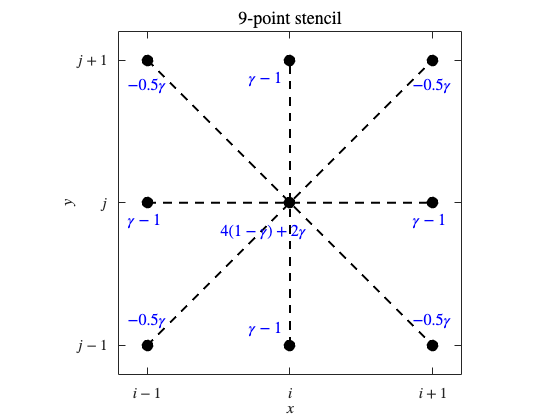

x2 = [-1 1];
y2 = [0 0];

figure
hold on; box on;
axis square;
set(gca,'fontsize',tickersize);
plot(x2, y2, 'o--', 'MarkerSize', msize - 0.5, 'LineWidth', width, 'MarkerFaceColor', black, 'Color', black);
plot(y2, x2, 'o--', 'MarkerSize', msize - 0.5, 'LineWidth', width, 'MarkerFaceColor', black, 'Color', black);
plot([-1 1], [1 -1], 'o--', 'MarkerSize', msize - 0.5, 'LineWidth', width, 'MarkerFaceColor', black, 'Color', black);
plot([-1 1], [-1 1], 'o--', 'MarkerSize', msize - 0.5, 'LineWidth', width, 'MarkerFaceColor', black, 'Color', black);
plot(y2, y2, 'o--', 'MarkerSize', msize - 0.5, 'LineWidth', width, 'MarkerFaceColor', black, 'Color', black);

text(-0.5, -0.2, '$4(1 - \gamma) + 2 \gamma$', 'FontSize', lsize + 3, 'Color', 'b', 'Interpreter', "latex");
text(-1.15, -0.12, '$\gamma - 1$', 'FontSize', lsize + 3, 'Color', 'b', 'Interpreter', "latex");
text(0.85, -0.12, '$\gamma - 1$', 'FontSize', lsize + 3, 'Color', 'b', 'Interpreter', "latex");
text(-0.3, 0.875, '$\gamma - 1$', 'FontSize', lsize + 3, 'Color', 'b', 'Interpreter', "latex");
text(-0.3, -0.875, '$\gamma - 1$', 'FontSize', lsize + 3, 'Color', 'b', 'Interpreter', "latex");

text(-1.15, -0.825, '$-0.5\gamma$', 'FontSize', lsize + 3, 'Color', 'b', 'Interpreter', "latex");
text(0.85, -0.825, '$-0.5\gamma$', 'FontSize', lsize + 3, 'Color', 'b', 'Interpreter', "latex");
text(-1.15, 0.825, '$-0.5\gamma$', 'FontSize', lsize + 3, 'Color', 'b', 'Interpreter', "latex");
text(0.85, 0.825, '$-0.5\gamma$', 'FontSize', lsize + 3, 'Color', 'b', 'Interpreter', "latex");

title('9-point stencil', 'FontSize', tsize + 4, 'Interpreter', "latex");
xlim([-1.2 1.2]); ylim([-1.2 1.2]);
ylabel('$y$', 'FontSize', lsize + 3), xlabel('$x$', 'FontSize', lsize + 3);
yticks([-1 0 1]); xticks([-1 0 1]);
yticklabel = {"$j-1$" "$j$" "$j+1$"};
xticklabel = {"$i-1$" "$i$" "$i+1$"};
set(gca, 'XTickLabels', xticklabel, 'TickLabelInterpreter', "latex");
set(gca, 'YTickLabels', yticklabel, 'TickLabelInterpreter', "latex");
hold off


ax = gca;
% exportgraphics(ax,'/Users/wayne/Desktop/pequod/manual/figs/9pointstencil.png','Resolution',1000);

## Space-Time Cell

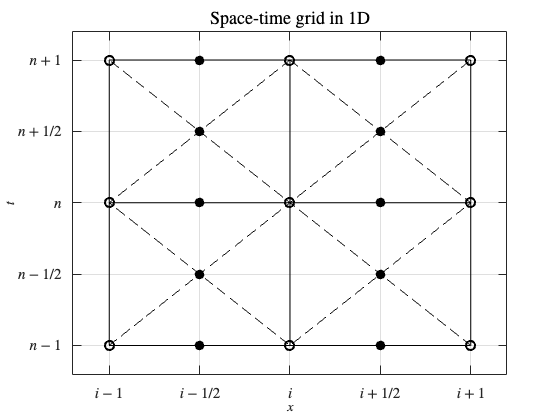

x = [-1 -1 1 1 -1];
y = [-1 1 1 -1 -1];
x2 = [-1 1];
y2 = [0 0];

figure
hold on; grid on; box on;
set(gca,'fontsize',tickersize)
% axis square
plot(x, y, 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
plot(x2, y2, 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
plot(y2, x2, 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
plot(x2, x2, 'LineStyle', '--', 'LineWidth', width - 1, "Color", black);
plot(-x2, x2, 'LineStyle', '--', 'LineWidth', width - 1, "Color", black);
plot([0 -1 0 1 0], [1 0 -1 0 1], 'LineStyle', '--', 'LineWidth', width - 1, "Color", black);
plot([-0.5 0.5 -0.5 0.5 -0.5 0.5 -0.5 0.5 -0.5 0.5], [-1 -1 -0.5 -0.5 0 0 0.5 0.5 1 1], 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'MarkerEdgeColor', black);
plot([-1 0 1 -1 0 1 -1 0 1], [-1 -1 -1 0 0 0 1 1 1], 'o', 'MarkerSize', msize - 1, 'LineWidth', width, 'Color', black);
% hold on
% pvec(0, 0, 1.1, 90, black, '-', width)
% pvec(0, 0, 1.1, 0, black, '-', width)
% hold off
title('Space-time grid in 1D', 'FontSize', tsize + 4, 'Interpreter', "latex");
% text(-0.15, 1.115, '$\xi_2$', 'FontSize', lsize + 3, 'Interpreter', "latex")
% text(1.07, -0.125, '$\xi_1$', 'FontSize', lsize + 3, 'Interpreter', "latex")
% text(-0.15, -0.1, '$(0, 0)$', 'FontSize', lsize + 3.5, 'Interpreter', "latex")
xlim([-1.2 1.2]); ylim([-1.2 1.2]);
ylabel('$t$', 'FontSize', lsize + 2), xlabel('$x$', 'FontSize', lsize + 2);
yticks([-1 -0.5 0 0.5 1]); xticks([-1 -0.5 0 0.5 1]);
yticklabel = {"$n-1$" "$n-1/2$" "$n$" "$n+1/2$" "$n+1$"};
xticklabel = {"$i-1$" "$i-1/2$" "$i$" "$i+1/2$" "$i+1$"};
set(gca, 'XTickLabels', xticklabel, 'TickLabelInterpreter', "latex")
set(gca, 'YTickLabels', yticklabel, 'TickLabelInterpreter', "latex")
hold off


ax = gca;
% exportgraphics(ax,'/Users/wayne/Desktop/Papers/CABARET/tex/figs/spacetimegrid.eps','Resolution',300)

## Conventional grid

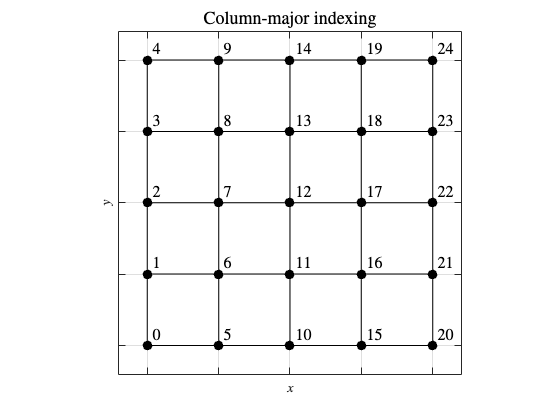

x = [-1 -1 1 1 -1];
y = [-1 1 1 -1 -1];
x2 = [-1 1];
y2 = [0 0];

figure
hold on; grid on; box on;
set(gca,'fontsize',tickersize);
axis square
plot(x, y, 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
plot(x2, y2, 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
plot(y2, x2, 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
plot([-0.5 -0.5], x2, 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
plot([0.5, 0.5], x2, 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
plot(x2, [-0.5 -0.5], 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
plot(x2, [0.5, 0.5], 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
plot(linspace(-1, 1, 5), [-0.5 -0.5 -0.5 -0.5 -0.5], 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);
plot(linspace(-1, 1, 5), [0.5 0.5 0.5 0.5 0.5], 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);
plot(linspace(-1, 1, 5), [-1 -1 -1 -1 -1], 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);
plot(linspace(-1, 1, 5), [0 0 0 0 0], 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);
plot(linspace(-1, 1, 5), [1 1 1 1 1], 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);


title('Column-major indexing', 'FontSize', tsize + 4, 'Interpreter', "latex");

text(-0.975, -0.925, '$0$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(-0.475, -0.925, '$5$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(0.025, -0.925, '$10$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(0.525, -0.925, '$15$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(1.025, -0.925, '$20$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(-0.975, -0.425, '$1$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(-0.475, -0.425, '$6$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(0.025, -0.425, '$11$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(0.525, -0.425, '$16$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(1.025, -0.425, '$21$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(-0.975, 0.075, '$2$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(-0.475, 0.075, '$7$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(0.025, 0.075, '$12$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(0.525, 0.075, '$17$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(1.025, 0.075, '$22$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(-0.975, 0.575, '$3$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(-0.475, 0.575, '$8$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(0.025, 0.575, '$13$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(0.525, 0.575, '$18$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(1.025, 0.575, '$23$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(-0.975, 1.075, '$4$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(-0.475, 1.075, '$9$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(0.025, 1.075, '$14$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(0.525, 1.075, '$19$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(1.025, 1.075, '$24$', 'FontSize', lsize + 3, 'Interpreter', "latex");

xlim([-1.2 1.2]); ylim([-1.2 1.2]);
ylabel('$y$', 'FontSize', lsize + 2), xlabel('$x$', 'FontSize', lsize + 2);
% yticks([-1 -0.5 0 0.5 1]); xticks([-1 -0.5 0 0.5 1]);
% yticklabel = {"n-1" "n-1/2" "n" "n+1/2" "n+1"};
% xticklabel = {"i-1/2" "i" "i+1/2" "i+1" "i+3/2"};
set(gca, 'XTickLabels', [], 'TickLabelInterpreter', "latex")
set(gca, 'YTickLabels', [], 'TickLabelInterpreter', "latex")
hold off


ax = gca;
% exportgraphics(ax,'/Users/wayne/Desktop/Papers/CABARET/tex/figs/cmfi.eps','Resolution',300)

## Column-major

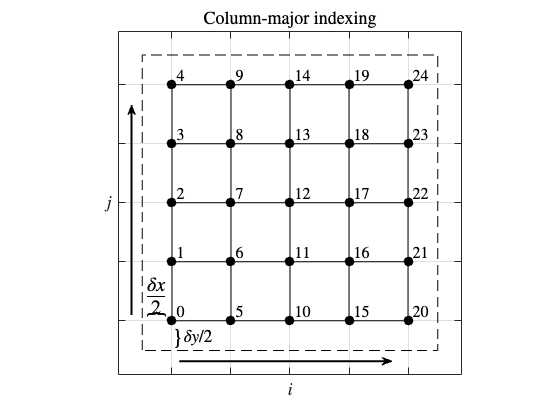

x = [-1 -1 1 1 -1];
y = [-1 1 1 -1 -1];
x2 = [-1 1];
y2 = [0 0];

figure
hold on; grid on; box on;
set(gca,'fontsize',tickersize);
axis square
plot(x, y, 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
plot(x2, y2, 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
plot(y2, x2, 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
plot([-0.5 -0.5], x2, 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
plot([0.5, 0.5], x2, 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
plot(x2, [-0.5 -0.5], 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
plot(x2, [0.5, 0.5], 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
plot(linspace(-1, 1, 5), [-0.5 -0.5 -0.5 -0.5 -0.5], 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);
plot(linspace(-1, 1, 5), [0.5 0.5 0.5 0.5 0.5], 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);
plot(linspace(-1, 1, 5), [-1 -1 -1 -1 -1], 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);
plot(linspace(-1, 1, 5), [0 0 0 0 0], 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);
plot(linspace(-1, 1, 5), [1 1 1 1 1], 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);

plot([-1.25 -1.25 1.25 1.25 -1.25], [-1.25 1.25 1.25 -1.25 -1.25], 'LineStyle', '--', 'LineWidth', width - 1, "Color", black);

title('Column-major indexing', 'FontSize', tsize + 4, 'Interpreter', "latex");

text(-0.975, -0.925, '$0$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(-0.475, -0.925, '$5$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(0.025, -0.925, '$10$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(0.525, -0.925, '$15$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(1.025, -0.925, '$20$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(-0.975, -0.425, '$1$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(-0.475, -0.425, '$6$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(0.025, -0.425, '$11$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(0.525, -0.425, '$16$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(1.025, -0.425, '$21$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(-0.975, 0.075, '$2$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(-0.475, 0.075, '$7$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(0.025, 0.075, '$12$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(0.525, 0.075, '$17$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(1.025, 0.075, '$22$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(-0.975, 0.575, '$3$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(-0.475, 0.575, '$8$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(0.025, 0.575, '$13$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(0.525, 0.575, '$18$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(1.025, 0.575, '$23$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(-0.975, 1.075, '$4$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(-0.475, 1.075, '$9$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(0.025, 1.075, '$14$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(0.525, 1.075, '$19$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(1.025, 1.075, '$24$', 'FontSize', lsize + 3, 'Interpreter', "latex");

text(-1.015, -1.14, '$\}$', 'FontSize', lsize + 9, 'Interpreter', "latex");
text(-0.915, -1.14, '$\delta y / 2$', 'FontSize', lsize + 4, 'Interpreter', "latex");
text(-1.14, -1.01, '$\}$', 'FontSize', lsize + 9, 'Interpreter', "latex", 'Rotation', 90);
text(-1.225, -0.79, '$\frac{\delta x}{2}$', 'FontSize', lsize + 8, 'Interpreter', "latex");

ahs = 10;
annotation('arrow', [0.32 0.7], [0.14 0.14], "HeadLength", ahs, "HeadWidth", ahs, 'LineWidth', width);
annotation('arrow', [0.235 0.235], [0.25 0.75], "HeadLength", ahs, "HeadWidth", ahs, 'LineWidth', width);

xlim([-1.45 1.45]); ylim([-1.45 1.45]);
ylabel('$j$', 'FontSize', lsize + 4, 'Rotation', 0), xlabel('$i$', 'FontSize', lsize + 4);
% yticks([-1 -0.5 0 0.5 1]); xticks([-1 -0.5 0 0.5 1]);
% yticklabel = {"n-1" "n-1/2" "n" "n+1/2" "n+1"};
% xticklabel = {"i-1/2" "i" "i+1/2" "i+1" "i+3/2"};
set(gca, 'XTickLabels', [], 'TickLabelInterpreter', "latex")
set(gca, 'YTickLabels', [], 'TickLabelInterpreter', "latex")
hold off


ax = gca;
% exportgraphics(ax,'/Users/wayne/Desktop/Papers/CABARET/tex/figs/cmfi.eps','Resolution',300)

## Onion numbering

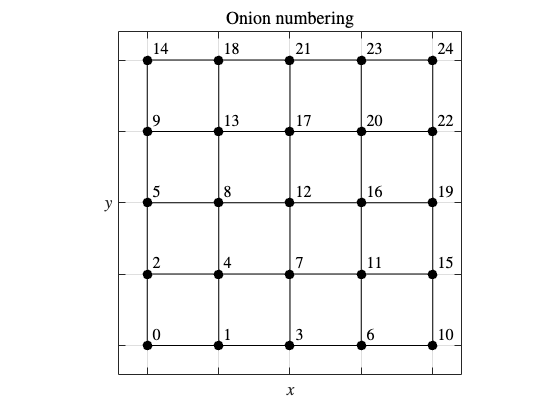

x = [-1 -1 1 1 -1];
y = [-1 1 1 -1 -1];
x2 = [-1 1];
y2 = [0 0];

figure
hold on; grid on; box on;
set(gca,'fontsize',tickersize);
axis square
plot(x, y, 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
plot(x2, y2, 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
plot(y2, x2, 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
plot([-0.5 -0.5], x2, 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
plot([0.5, 0.5], x2, 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
plot(x2, [-0.5 -0.5], 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
plot(x2, [0.5, 0.5], 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
plot(linspace(-1, 1, 5), [-0.5 -0.5 -0.5 -0.5 -0.5], 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);
plot(linspace(-1, 1, 5), [0.5 0.5 0.5 0.5 0.5], 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);
plot(linspace(-1, 1, 5), [-1 -1 -1 -1 -1], 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);
plot(linspace(-1, 1, 5), [0 0 0 0 0], 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);
plot(linspace(-1, 1, 5), [1 1 1 1 1], 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);

title('Onion numbering', 'FontSize', tsize + 4, 'Interpreter', "latex");

text(-0.975, -0.925, '$0$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(-0.475, -0.925, '$1$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(0.025, -0.925, '$3$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(0.525, -0.925, '$6$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(1.025, -0.925, '$10$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(-0.975, -0.425, '$2$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(-0.475, -0.425, '$4$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(0.025, -0.425, '$7$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(0.525, -0.425, '$11$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(1.025, -0.425, '$15$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(-0.975, 0.075, '$5$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(-0.475, 0.075, '$8$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(0.025, 0.075, '$12$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(0.525, 0.075, '$16$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(1.025, 0.075, '$19$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(-0.975, 0.575, '$9$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(-0.475, 0.575, '$13$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(0.025, 0.575, '$17$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(0.525, 0.575, '$20$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(1.025, 0.575, '$22$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(-0.975, 1.075, '$14$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(-0.475, 1.075, '$18$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(0.025, 1.075, '$21$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(0.525, 1.075, '$23$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(1.025, 1.075, '$24$', 'FontSize', lsize + 3, 'Interpreter', "latex");

xlim([-1.2 1.2]); ylim([-1.2 1.2]);
ylabel('$y$', 'FontSize', lsize + 4, 'Rotation', 0), xlabel('$x$', 'FontSize', lsize + 4);
% yticks([-1 -0.5 0 0.5 1]); xticks([-1 -0.5 0 0.5 1]);
% yticklabel = {"n-1" "n-1/2" "n" "n+1/2" "n+1"};
% xticklabel = {"i-1/2" "i" "i+1/2" "i+1" "i+3/2"};
set(gca, 'XTickLabels', [], 'TickLabelInterpreter', "latex")
set(gca, 'YTickLabels', [], 'TickLabelInterpreter', "latex")
hold off


ax = gca;
% exportgraphics(ax,'/Users/wayne/Desktop/Papers/ESA/figs/onion.eps','Resolution',300)

## Mixed indexing

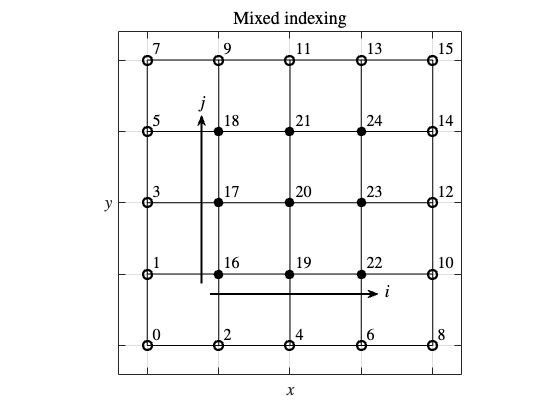

x = [-1 -1 1 1 -1];
y = [-1 1 1 -1 -1];
x2 = [-1 1];
y2 = [0 0];

figure
hold on; grid on; box on;
set(gca,'fontsize',tickersize);
axis square
plot(x, y, 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
plot(x2, y2, 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
plot(y2, x2, 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
plot([-0.5 -0.5], x2, 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
plot([0.5, 0.5], x2, 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
plot(x2, [-0.5 -0.5], 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
plot(x2, [0.5, 0.5], 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
plot(linspace(-0.5, 0.5, 3), [-0.5 -0.5 -0.5], 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);
plot(linspace(-0.5, 0.5, 3), [0.5 0.5 0.5], 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);
plot(linspace(-0.5, 0.5, 3), [0 0 0], 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);

plot([-1 -1 -1], linspace(-0.5, 0.5, 3), 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', 'none', 'Color', black, 'LineWidth', 2.25);
plot([1 1 1], linspace(-0.5, 0.5, 3), 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', 'none', 'Color', black, 'LineWidth', 2.25);
plot(linspace(-1, 1, 5), [1 1 1 1 1], 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', 'none', 'Color', black, 'LineWidth', 2.25);
plot(linspace(-1, 1, 5), [-1 -1 -1 -1 -1], 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', 'none', 'Color', black, 'LineWidth', 2.25);

title('Mixed indexing', 'FontSize', tsize + 4, 'Interpreter', "latex");

text(-0.975, -0.925, '$0$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(-0.475, -0.925, '$2$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(0.025, -0.925, '$4$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(0.525, -0.925, '$6$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(1.025, -0.925, '$8$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(-0.975, -0.425, '$1$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(-0.475, -0.425, '$16$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(0.025, -0.425, '$19$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(0.525, -0.425, '$22$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(1.025, -0.425, '$10$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(-0.975, 0.075, '$3$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(-0.475, 0.075, '$17$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(0.025, 0.075, '$20$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(0.525, 0.075, '$23$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(1.025, 0.075, '$12$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(-0.975, 0.575, '$5$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(-0.475, 0.575, '$18$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(0.025, 0.575, '$21$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(0.525, 0.575, '$24$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(1.025, 0.575, '$14$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(-0.975, 1.075, '$7$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(-0.475, 1.075, '$9$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(0.025, 1.075, '$11$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(0.525, 1.075, '$13$', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(1.025, 1.075, '$15$', 'FontSize', lsize + 3, 'Interpreter', "latex");

text(0.65, -0.625, '$i$', 'FontSize', lsize + 4, 'Interpreter', "latex");
text(-0.66, 0.7, '$j$', 'FontSize', lsize + 4, 'Interpreter', "latex");

ahs = 10;
annotation('arrow', [0.375 0.675], [0.3 0.3], "HeadLength", ahs, "HeadWidth", ahs, 'LineWidth', width);
annotation('arrow', [0.36 0.36], [0.325 0.725], "HeadLength", ahs, "HeadWidth", ahs, 'LineWidth', width);

xlim([-1.2 1.2]); ylim([-1.2 1.2]);
ylabel('$y$', 'FontSize', lsize + 4, 'Rotation', 0), xlabel('$x$', 'FontSize', lsize + 4);
set(gca, 'XTickLabels', [], 'TickLabelInterpreter', "latex")
set(gca, 'YTickLabels', [], 'TickLabelInterpreter', "latex")
hold off


ax = gca;
% exportgraphics(ax,'/Users/wayne/Desktop/Papers/ESA/figs/mixed_index.eps','Resolution',300)

## Arakawa C-grid

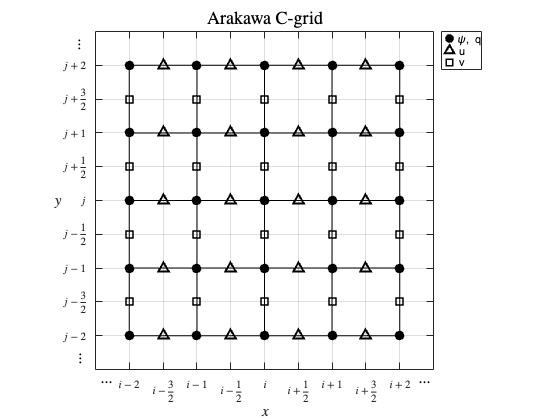

x = [-1 -1 1 1 -1];
y = [-1 1 1 -1 -1];
x2 = [-1 1];
y2 = [0 0];

figure
hold on; grid on; box on;
axis square
plot(x, y, 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
plot([-1 -1], x2, 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
plot([1 1], x2, 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
plot(x2, [-1 -1], 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
plot(x2, [1 1], 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);

plot(x2, y2, 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
plot(y2, x2, 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
plot([-0.5 -0.5], x2, 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
plot([0.5, 0.5], x2, 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
plot(x2, [-0.5 -0.5], 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
plot(x2, [0.5, 0.5], 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
plot(linspace(-1, 1, 5), -0.5 * ones(length(5), 1), 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);
plot(linspace(-1, 1, 5), 0.5 * ones(length(5), 1), 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);
plot(linspace(-1, 1, 5), -1 * ones(length(5), 1), 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);
plot(linspace(-1, 1, 5), zeros(length(5), 1), 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);
plot(linspace(-1, 1, 5), ones(length(5), 1), 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);
plot(linspace(-0.75, 0.75, 4), -1 * ones(length(4), 1), '^', 'MarkerSize', msize - 1, 'LineWidth', width, 'Color', black);
plot(linspace(-0.75, 0.75, 4), -0.5 * ones(length(4), 1), '^', 'MarkerSize', msize - 1, 'LineWidth', width, 'Color', black);
plot(linspace(-0.75, 0.75, 4), zeros(length(4), 1), '^', 'MarkerSize', msize - 1, 'LineWidth', width, 'Color', black);
plot(linspace(-0.75, 0.75, 4), 0.5 * ones(length(4), 1), '^', 'MarkerSize', msize - 1, 'LineWidth', width, 'Color', black);
plot(linspace(-0.75, 0.75, 4), ones(length(4), 1), '^', 'MarkerSize', msize - 1, 'LineWidth', width, 'Color', black);
plot(linspace(-1., 1., 5), -0.75 * ones(length(5), 1), 's', 'MarkerSize', msize - 1, 'LineWidth', width, 'Color', black);
plot(linspace(-1., 1., 5), -0.25 * ones(length(5), 1), 's', 'MarkerSize', msize - 1, 'LineWidth', width, 'Color', black);
plot(linspace(-1., 1., 5), 0.25 * ones(length(5), 1), 's', 'MarkerSize', msize - 1, 'LineWidth', width, 'Color', black);
plot(linspace(-1., 1., 5), 0.75 * ones(length(5), 1), 's', 'MarkerSize', msize - 1, 'LineWidth', width, 'Color', black);

% plot(linspace(-0.75, 0.75, 4), -0.75 * ones(length(4), 1), 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);
% plot(linspace(-0.75, 0.75, 4), -0.25 * ones(length(4), 1), 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);
% plot(linspace(-0.75, 0.75, 4), 0.25 * ones(length(4), 1), 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);
% plot(linspace(-0.75, 0.75, 4), 0.75 * ones(length(4), 1), 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);

text(-1.225, -1.315, '...', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(1.125, -1.315, '...', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(-1.395, -1.225, '...', 'FontSize', lsize + 3, 'Interpreter', "latex", 'rotation', 90);
text(-1.4, 1.1, '...', 'FontSize', lsize + 3, 'Interpreter', "latex", 'rotation', 90);

plt1 = plot(-1., -0.5, 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);
plt2 = plot(-0.75, -1., '^', 'MarkerSize', msize - 1, 'LineWidth', width, 'Color', black);
plt3 = plot(-1., -0.75, 's', 'MarkerSize', msize - 1, 'LineWidth', width, 'Color', black);

L = legend([plt1 plt2 plt3], '\psi, q', ' u', ' v', 'Location', 'northeastoutside', 'Interpreter', 'tex');
L.FontSize = legsize;

title('Arakawa C-grid', 'FontSize', tsize + 4, 'Interpreter', "latex");
xlim([-1.25 1.25]); ylim([-1.25 1.25]);
ylabel('$y$', 'FontSize', lsize + 2, 'Rotation', 0), xlabel('$x$', 'FontSize', lsize + 2);
yticks(linspace(-1., 1., 9)); xticks(linspace(-1., 1., 9));
yticklabel = {"$j-2$" "$j-\frac{3}{2}$" "$j-1$" "$j-\frac{1}{2}$" "$j$" "$j+\frac{1}{2}$" "$j+1$" "$j+\frac{3}{2}$" "$j+2$"};
xticklabel = {"$i-2$" "$i-\frac{3}{2}$" "$i-1$" "$i-\frac{1}{2}$" "$i$" "$i+\frac{1}{2}$" "$i+1$" "$i+\frac{3}{2}$" "$i+2$"};
set(gca, 'XTickLabels', xticklabel, 'TickLabelInterpreter', "latex");
set(gca, 'YTickLabels', yticklabel, 'TickLabelInterpreter', "latex");
xtickangle(0)
hold off

ax = gca;
ax.XAxis.FontSize = tickersize - 4;
ax.YAxis.FontSize = tickersize - 4;
ax.XLabel.FontSize = tickersize;
ax.YLabel.FontSize = tickersize;

## Double periodic

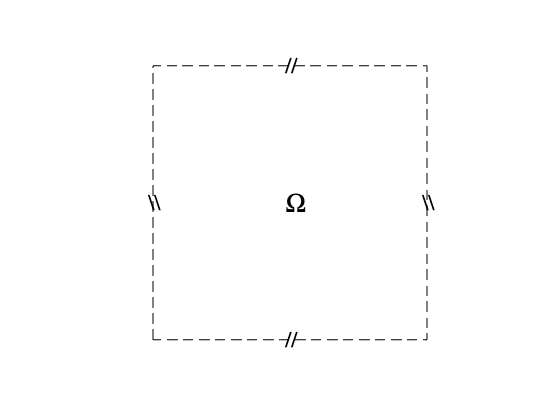

x = [-1 -1 1 1 -1];
y = [-1 1 1 -1 -1];

figure
hold on; grid off; box off;
axis square
plot(x, y, 'LineStyle', '--', 'LineWidth', width - 1, "Color", black);

text(-0.05, 0, '$\Omega$', 'FontSize', lsize + 14, 'Interpreter', 'latex');
text(-0.05, 1, '//', 'FontSize', lsize + 9, 'Interpreter', 'latex');
text(-0.05, -1, '//', 'FontSize', lsize + 9, 'Interpreter', 'latex');
text(-1.05, 0, '$\backslash \backslash$', 'FontSize', lsize + 9, 'Interpreter', 'latex');
text(0.95, 0, '$\backslash \backslash$', 'FontSize', lsize + 9, 'Interpreter', 'latex');

xlim([-1.25 1.25]); ylim([-1.25 1.25]);
hold off

ax = gca;
set(ax, 'Visible', 'off');
set(ax, 'XTick', []);
set(ax, 'YTick', []);

## Channel

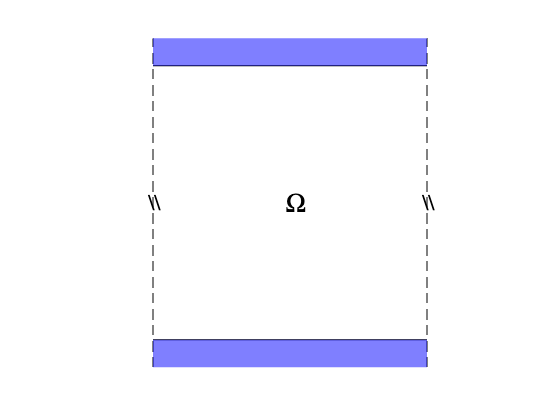

x1 = [-1 1 1 -1];
y1 = [1 1 1.2 1.2];
y2 = [-1 -1 -1.2 -1.2];

figure
hold on; grid off; box off;
axis square
plot([-1 -1], [-1.2 1.2], 'LineStyle', '--', 'LineWidth', width - 1, "Color", black);
plot([1 1], [-1.2 1.2], 'LineStyle', '--', 'LineWidth', width - 1, "Color", black);
plot([-1 1], [-1 -1], 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
plot([-1 1], [1 1], 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);

text(-0.05, 0, '$\Omega$', 'FontSize', lsize + 14, 'Interpreter', 'latex');
text(-1.05, 0, '$\backslash \backslash$', 'FontSize', lsize + 9, 'Interpreter', 'latex');
text(0.95, 0, '$\backslash \backslash$', 'FontSize', lsize + 9, 'Interpreter', 'latex');

xlim([-1.25 1.25]); ylim([-1.25 1.25]);
p1 = patch(x1, y1, 'b');
p2 = patch(x1, y2, 'b');
set(p1, 'facealpha', '0.5');
set(p1, 'EdgeColor', 'none');
set(p2, 'facealpha', '0.5');
set(p2, 'EdgeColor', 'none');

hold off

ax = gca;
set(ax, 'Visible', 'off');
set(ax, 'XTick', []);
set(ax, 'YTick', []);

## Basin

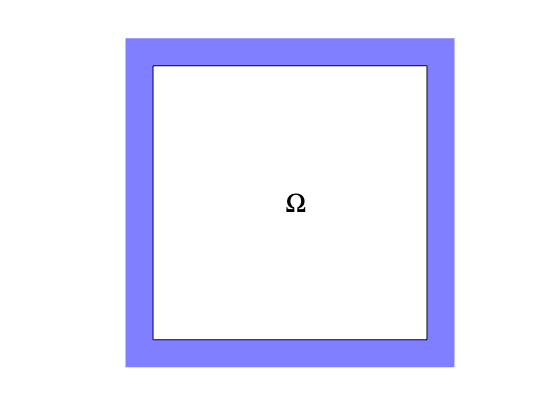

x = [-1 -1 1 1 -1];
y = [-1 1 1 -1 -1];
x1 = [-1 1 1 -1];
x2 = [-1.2 1.2 1.2 -1.2];
y1 = [1 1 1.2 1.2];
y2 = [-1 -1 -1.2 -1.2];

figure
hold on; grid off; box off;
axis square
plot(x, y, 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);

text(-0.05, 0, '$\Omega$', 'FontSize', lsize + 14, 'Interpreter', 'latex');

xlim([-1.25 1.25]); ylim([-1.25 1.25]);
p1 = patch(x1, y1, 'b');
p2 = patch(x1, y2, 'b');
p3 = patch(y1, x2, 'b');
p4 = patch(y2, x2, 'b');
set(p1, 'facealpha', '0.5');
set(p1, 'EdgeColor', 'none');
set(p2, 'facealpha', '0.5');
set(p2, 'EdgeColor', 'none');
set(p3, 'facealpha', '0.5');
set(p3, 'EdgeColor', 'none');
set(p4, 'facealpha', '0.5');
set(p4, 'EdgeColor', 'none');

hold off

ax = gca;
set(ax, 'Visible', 'off');
set(ax, 'XTick', []);
set(ax, 'YTick', []);

## Double periodic domain

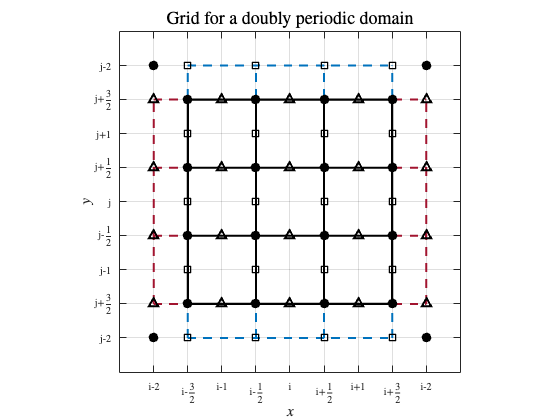

x = [-0.75 -0.75 0.75 0.75 -0.75];
y = [-0.75 0.75 0.75 -0.75 -0.75];
x2 = [-0.75 0.75];
y2 = [-1. 1.];

figure
hold on; grid on; box on;
% set(gca,'fontsize',tickersize);
axis square
plot(x, y, 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
plot(y2, [0.25 0.25], 'LineStyle', '--', 'LineWidth', width, "Color", red);
plot(y2, [-0.25 -0.25], 'LineStyle', '--', 'LineWidth', width, "Color", red);
plot(y2, [-0.75 -0.75], 'LineStyle', '--', 'LineWidth', width, "Color", red);
plot(y2, [0.75, 0.75], 'LineStyle', '--', 'LineWidth', width, "Color", red);
plot(x2, [-1. -1.], 'LineStyle', '--', 'LineWidth', width, "Color", blue);
plot(x2, [1., 1.], 'LineStyle', '--', 'LineWidth', width, "Color", blue);

plot([-0.25 -0.25], y2, 'LineStyle', '--', 'LineWidth', width, "Color", blue);
plot([-0.75 -0.75], y2, 'LineStyle', '--', 'LineWidth', width, "Color", blue);
plot([0.75, 0.75], y2, 'LineStyle', '--', 'LineWidth', width, "Color", blue);
plot([0.25 0.25], y2, 'LineStyle', '--', 'LineWidth', width, "Color", blue);
plot([1., 1.], x2, 'LineStyle', '--', 'LineWidth', width, "Color", red);
plot([-1. -1.], x2, 'LineStyle', '--', 'LineWidth', width, "Color", red);

plot(x2, [0.25 0.25], 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot([0.25 0.25], x2, 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot(x2, [-0.25 -0.25], 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot([-0.25 -0.25], x2, 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot([-0.75 -0.75], x2, 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot([0.75, 0.75], x2, 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot(x2, [-0.75 -0.75], 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot(x2, [0.75, 0.75], 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);

plot(linspace(-0.75, 0.75, 4), -0.25 * ones(length(4), 1), 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);
plot(linspace(-0.75, 0.75, 4), 0.25 * ones(length(4), 1), 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);
plot(linspace(-0.75, 0.75, 4), 0.75 * ones(length(4), 1), 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);
plot(linspace(-0.75, 0.75, 4), -0.75 * ones(length(4), 1), 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);
plot([-1., -1., 1., 1.], [-1., 1., -1., 1.], 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);
% plot(linspace(-0.75, 0.75, 4), -1.25 * ones(length(4), 1), 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);

plot(linspace(-0.75, 0.75, 4), -1 * ones(length(4), 1), 's', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);
plot(linspace(-0.75, 0.75, 4), -0.5 * ones(length(4), 1), 's', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);
plot(linspace(-0.75, 0.75, 4), zeros(length(4), 1), 's', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);
plot(linspace(-0.75, 0.75, 4), 0.5 * ones(length(4), 1), 's', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);
plot(linspace(-0.75, 0.75, 4), ones(length(4), 1), 's', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);

% plot(linspace(-0.5, 0.5, 3), -1.25 * ones(length(3), 1), '^', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);
plot(linspace(-1., 1., 5), -0.75 * ones(length(5), 1), '^', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);
plot(linspace(-1., 1., 5), -0.25 * ones(length(5), 1), '^', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);
plot(linspace(-1., 1., 5), 0.25 * ones(length(5), 1), '^', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);
plot(linspace(-1., 1., 5), 0.75 * ones(length(5), 1), '^', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);
% plot(linspace(-0.5, 0.5, 3), 1.25 * ones(length(3), 1), '^', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);

title('Grid for a doubly periodic domain', 'FontSize', tsize + 4, 'Interpreter', "latex");
xlim([-1.25 1.25]); ylim([-1.25 1.25]);
ylabel('$y$', 'FontSize', lsize + 2), xlabel('$x$', 'FontSize', lsize + 2);
yticks(linspace(-1., 1., 9)); xticks(linspace(-1., 1., 9));
yticklabel = {"j-2" "j+$\frac{3}{2}$" "j-1" "j-$\frac{1}{2}$" "j" "j+$\frac{1}{2}$" "j+1" "j+$\frac{3}{2}$" "j-2"};
xticklabel = {"i-2" "i-$\frac{3}{2}$" "i-1" "i-$\frac{1}{2}$" "i" "i+$\frac{1}{2}$" "i+1" "i+$\frac{3}{2}$" "i-2"};
set(gca, 'XTickLabels', xticklabel, 'TickLabelInterpreter', "latex");
set(gca, 'YTickLabels', yticklabel, 'TickLabelInterpreter', "latex");
xtickangle(0)
hold off

ax = gca;
ax.XAxis.FontSize = tickersize - 5;
ax.YAxis.FontSize = tickersize - 5;
ax.XLabel.FontSize = tickersize;
ax.YLabel.FontSize = tickersize;

## Rectangular domain

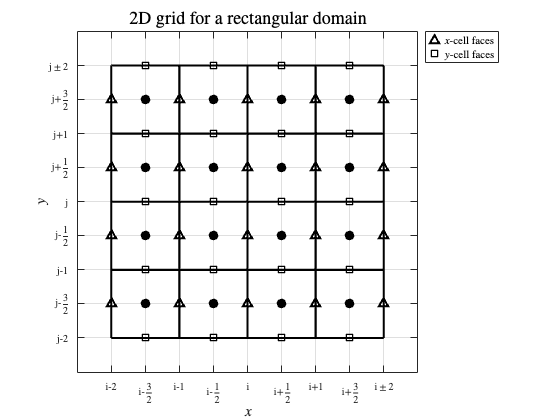

x = [-0.75 -0.75 0.75 0.75 -0.75];
y = [-0.75 0.75 0.75 -0.75 -0.75];
x2 = [-1. 1.]; % = [-0.75 0.75];

figure
hold on; grid on; box on;
% set(gca,'fontsize',tickersize);
axis square
% plot(x, y, 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
% plot(y2, [0.25 0.25], 'LineStyle', '--', 'LineWidth', width, "Color", red);
% plot(y2, [-0.25 -0.25], 'LineStyle', '--', 'LineWidth', width, "Color", red);
% plot(y2, [-0.75 -0.75], 'LineStyle', '--', 'LineWidth', width, "Color", red);
% plot(y2, [0.75, 0.75], 'LineStyle', '--', 'LineWidth', width, "Color", red);
% plot(x2, [-1. -1.], 'LineStyle', '--', 'LineWidth', width, "Color", blue);
% plot(x2, [1., 1.], 'LineStyle', '--', 'LineWidth', width, "Color", blue);
% 
% plot([-0.25 -0.25], y2, 'LineStyle', '--', 'LineWidth', width, "Color", blue);
% plot([-0.75 -0.75], y2, 'LineStyle', '--', 'LineWidth', width, "Color", blue);
% plot([0.75, 0.75], y2, 'LineStyle', '--', 'LineWidth', width, "Color", blue);
% plot([0.25 0.25], y2, 'LineStyle', '--', 'LineWidth', width, "Color", blue);
% plot([1., 1.], x2, 'LineStyle', '--', 'LineWidth', width, "Color", red);
% plot([-1. -1.], x2, 'LineStyle', '--', 'LineWidth', width, "Color", red);

plot(x2, [0. 0.], 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot([0. 0.], x2, 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot(x2, [-0.5 -0.5], 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot([-0.5 -0.5], x2, 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot([-1. -1.], x2, 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot([1., 1.], x2, 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot(x2, [-1. -1.], 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot(x2, [1., 1.], 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot([0.5, 0.5], x2, 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot(x2, [0.5 0.5], 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);

plot(linspace(-0.75, 0.75, 4), -0.25 * ones(length(4), 1), 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);
plot(linspace(-0.75, 0.75, 4), 0.25 * ones(length(4), 1), 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);
plot(linspace(-0.75, 0.75, 4), 0.75 * ones(length(4), 1), 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);
plot(linspace(-0.75, 0.75, 4), -0.75 * ones(length(4), 1), 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);
% plot(linspace(-0.75, 0.75, 4), -1.25 * ones(length(4), 1), 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);

plot(linspace(-0.75, 0.75, 4), -0.5 * ones(length(4), 1), 's', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);
plot(linspace(-0.75, 0.75, 4), zeros(length(4), 1), 's', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);
plot(linspace(-0.75, 0.75, 4), 0.5 * ones(length(4), 1), 's', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);
plot(linspace(-0.75, 0.75, 4), ones(length(4), 1), 's', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);

plot(linspace(-1., 1., 5), -0.25 * ones(length(5), 1), '^', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);
plot(linspace(-1., 1., 5), 0.25 * ones(length(5), 1), '^', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);
plot(linspace(-1., 1., 5), 0.75 * ones(length(5), 1), '^', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);
% plot(linspace(-0.5, 0.5, 3), 1.25 * ones(length(3), 1), '^', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);

plot1 = plot([-0.75 -0.25 0.25 0.75], [-1. -1. -1. -1.], 's', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);
plot2 = plot([-1. -0.5 0 0.5 1.], [-0.75 -0.75 -0.75 -0.75 -0.75], '^', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);
L = legend([plot2 plot1], '$x$-cell faces', '$y$-cell faces', 'Location', 'northeastoutside');
L.FontSize = legsize;

% title('Grid for a single periodic/channel domain', 'FontSize', tsize + 4, 'Interpreter', "latex");
title('2D grid for a rectangular domain', 'FontSize', tsize + 4, 'Interpreter', "latex");
xlim([-1.25 1.25]); ylim([-1.25 1.25]);
ylabel('$y$', 'FontSize', lsize + 2), xlabel('$x$', 'FontSize', lsize + 2);
yticks(linspace(-1., 1., 9)); xticks(linspace(-1., 1., 9));
yticklabel = {"j-2" "j-$\frac{3}{2}$" "j-1" "j-$\frac{1}{2}$" "j" "j+$\frac{1}{2}$" "j+1" "j+$\frac{3}{2}$" "j$\pm$2"};
xticklabel = {"i-2" "i-$\frac{3}{2}$" "i-1" "i-$\frac{1}{2}$" "i" "i+$\frac{1}{2}$" "i+1" "i+$\frac{3}{2}$" "i$\pm$2"};
set(gca, 'XTickLabels', xticklabel, 'TickLabelInterpreter', "latex");
set(gca, 'YTickLabels', yticklabel, 'TickLabelInterpreter', "latex");
xtickangle(0)
hold off

ax = gca;
ax.XAxis.FontSize = tickersize - 5;
ax.YAxis.FontSize = tickersize - 5;
ax.XLabel.FontSize = tickersize;
ax.YLabel.FontSize = tickersize;

% exportgraphics(ax,'/Users/wayne/Desktop/Papers/CABARET/tex/figs/2dgrid.png','Resolution',600)

## Irregular domain

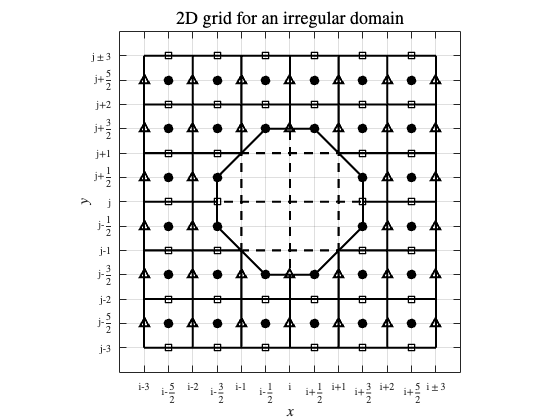

x2 = [-1.5 1.5];

figure
hold on; grid on; box on;
% set(gca,'fontsize',tickersize);
axis square

plot(x2, [0. 0.], 'LineStyle', '--', 'LineWidth', width + 0.1, "Color", black);
plot([0. 0.], x2, 'LineStyle', '--', 'LineWidth', width + 0.1, "Color", black);
plot(x2, [-0.5 -0.5], 'LineStyle', '--', 'LineWidth', width + 0.1, "Color", black);
plot([-0.5 -0.5], x2, 'LineStyle', '--', 'LineWidth', width + 0.1, "Color", black);
plot([-1. -1.], x2, 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot([1., 1.], x2, 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot(x2, [-1. -1.], 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot(x2, [1., 1.], 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot([0.5, 0.5], x2, 'LineStyle', '--', 'LineWidth', width + 0.1, "Color", black);
plot(x2, [0.5 0.5], 'LineStyle', '--', 'LineWidth', width + 0.1, "Color", black);
plot([-1.5 -1.5], x2, 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot([1.5, 1.5], x2, 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot(x2, [-1.5 -1.5], 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot(x2, [1.5, 1.5], 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);

plot([-1.5 -0.75], [0. 0.], 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot([0. 0.], [-1.5 -0.75], 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot([0.75 1.5], [0. 0.], 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot([0. 0.], [0.75 1.5], 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot([-1.5 -0.5], [-0.5 -0.5], 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot([-0.5 -0.5], [-1.5 -0.5], 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot([0.5 1.5], [-0.5 -0.5], 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot([-0.5 -0.5], [0.5 1.5], 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot([-1.5 -0.5], [0.5 0.5], 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot([0.5 0.5], [-1.5 -0.5], 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot([0.5 1.5], [0.5 0.5], 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot([0.5 0.5], [0.5 1.5], 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);

plot(linspace(-1.25, 1.25, 6), -1.25 * ones(length(6), 1), 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);
plot(linspace(-1.25, 1.25, 6), -0.75 * ones(length(6), 1), 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);
plot([-1.25 -0.75 0.75 1.25], -0.25 * ones(length(4), 1), 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);
plot([-1.25 -0.75 0.75 1.25], 0.25 * ones(length(4), 1), 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);
plot(linspace(-1.25, 1.25, 6), 0.75 * ones(length(6), 1), 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);
plot(linspace(-1.25, 1.25, 6), 1.25 * ones(length(6), 1), 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);

plot(linspace(-1.25, 1.25, 6), -1.5 * ones(length(6), 1), 's', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);
plot1 = plot([-1.25 -0.75 -0.25 0.25 0.75 1.25], [-1. -1. -1. -1. -1. -1.], 's', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);
plot([-1.25 -0.75 0.75 1.25], -0.5 * ones(length(4), 1), 's', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);
plot([-1.25 -0.75 0.75 1.25], zeros(length(4), 1), 's', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);
plot([-1.25 -0.75 0.75 1.25], 0.5 * ones(length(4), 1), 's', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);
plot(linspace(-1.25, 1.25, 6), ones(length(6), 1), 's', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);
plot(linspace(-1.25, 1.25, 6), 1.5 * ones(length(6), 1), 's', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);

plot(linspace(-1.5, 1.5, 7), -1.25 * ones(length(7), 1), '^', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);
plot2 = plot([-1.5 -1. -0.5 0 0.5 1. 1.5], [-0.75 -0.75 -0.75 -0.75 -0.75 -0.75 -0.75], '^', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);
plot([-1.5 -1. 1. 1.5], -0.25 * ones(length(4), 1), '^', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);
plot([-1.5 -1. 1. 1.5], 0.25 * ones(length(4), 1), '^', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);
plot(linspace(-1.5, 1.5, 7), 0.75 * ones(length(7), 1), '^', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);
plot(linspace(-1.5, 1.5, 7), 1.25 * ones(length(7), 1), '^', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);

plot([-0.25 -0.75 -0.75 -0.25 0.25 0.75 0.75 0.25 -0.25], [0.75 0.25 -0.25 -0.75 -0.75 -0.25 0.25 0.75 0.75], 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);

% L = legend([plot2 plot1], '$x$-cell faces', '$y$-cell faces', 'Location', 'northeastoutside');
% L.FontSize = legsize;

title('2D grid for an irregular domain', 'FontSize', tsize + 4, 'Interpreter', "latex");
xlim([-1.75 1.75]); ylim([-1.75 1.75]);
ylabel('$y$', 'FontSize', lsize + 2), xlabel('$x$', 'FontSize', lsize + 2);
yticks(linspace(-1.5, 1.5, 13)); xticks(linspace(-1.5, 1.5, 13));
yticklabel = {"j-3" "j-$\frac{5}{2}$" "j-2" "j-$\frac{3}{2}$" "j-1" "j-$\frac{1}{2}$" "j" "j+$\frac{1}{2}$" "j+1" "j+$\frac{3}{2}$" "j+2" "j+$\frac{5}{2}$" "j$\pm$3"};
xticklabel = {"i-3" "i-$\frac{5}{2}$" "i-2" "i-$\frac{3}{2}$" "i-1" "i-$\frac{1}{2}$" "i" "i+$\frac{1}{2}$" "i+1" "i+$\frac{3}{2}$" "i+2" "i+$\frac{5}{2}$" "i$\pm$3"};
set(gca, 'XTickLabels', xticklabel, 'TickLabelInterpreter', "latex");
set(gca, 'YTickLabels', yticklabel, 'TickLabelInterpreter', "latex");
xtickangle(0)
hold off

ax = gca;
ax.XAxis.FontSize = tickersize - 5;
ax.YAxis.FontSize = tickersize - 5;
ax.XLabel.FontSize = tickersize;
ax.YLabel.FontSize = tickersize;

% exportgraphics(ax,'/Users/wayne/Desktop/Papers/CABARET/tex/figs/2dirregular.png','Resolution',600)

## Irregular BCs

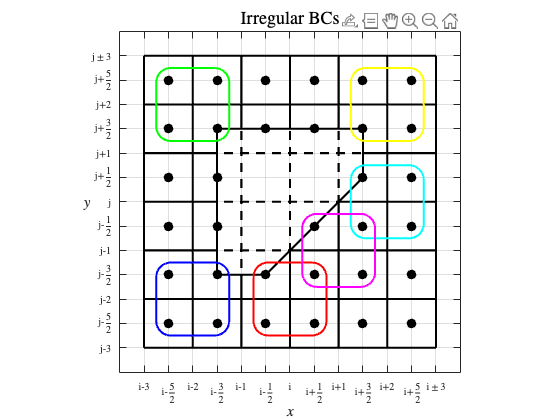

x2 = [-1.5 1.5];

figure
hold on; grid on; box on;
% set(gca,'fontsize',tickersize);
axis square

plot(x2, [0. 0.], 'LineStyle', '--', 'LineWidth', width + 0.1, "Color", black);
plot([0. 0.], x2, 'LineStyle', '--', 'LineWidth', width + 0.1, "Color", black);
plot(x2, [-0.5 -0.5], 'LineStyle', '--', 'LineWidth', width + 0.1, "Color", black);
plot([-0.5 -0.5], x2, 'LineStyle', '--', 'LineWidth', width + 0.1, "Color", black);
plot([0.5, 0.5], x2, 'LineStyle', '--', 'LineWidth', width + 0.1, "Color", black);
plot(x2, [0.5 0.5], 'LineStyle', '--', 'LineWidth', width + 0.1, "Color", black);

% plot([1., 1.], [-1.5 -1.], 'LineStyle', '--', 'LineWidth', width + 0.1, "Color", black);
% plot([1. 1.5], [-1. -1.], 'LineStyle', '--', 'LineWidth', width + 0.1, "Color", black);

plot([-1.5 -1.5], x2, 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot([1.5, 1.5], x2, 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot(x2, [-1.5 -1.5], 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot(x2, [1.5, 1.5], 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);

plot([-1. -1.], x2, 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot([1., 1.], x2, 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot(x2, [-1. -1.], 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot(x2, [1., 1.], 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);

plot([-1.5 -0.75], [0. 0.], 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot([0. 0.], [-1.5 -0.5], 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot([0.5 1.5], [0. 0.], 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot([0. 0.], [0.75 1.5], 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot([-1.5 -0.75], [-0.5 -0.5], 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot([-0.5 -0.5], [-1.5 -0.75], 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot([0. 1.5], [-0.5 -0.5], 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot([-0.5 -0.5], [0.75 1.5], 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot([-1.5 -0.75], [0.5 0.5], 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot([0.5 0.5], [-1.5 0.], 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot([0.75 1.5], [0.5 0.5], 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot([0.5 0.5], [0.75 1.5], 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);

% plot3 = plot([0.5 1.5], [-1.5 -0.5], 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);

plot(linspace(-1.25, 1.25, 6), -1.25 * ones(length(6), 1), 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);
plot(linspace(-1.25, 1.25, 6), -0.75 * ones(length(6), 1), 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);
plot([-1.25 -0.75 0.25 0.75 1.25], -0.25 * ones(length(5), 1), 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);
plot([-1.25 -0.75 0.75 1.25], 0.25 * ones(length(4), 1), 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);
plot(linspace(-1.25, 1.25, 6), 0.75 * ones(length(6), 1), 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);
plot(linspace(-1.25, 1.25, 6), 1.25 * ones(length(6), 1), 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);

% plot(linspace(-1.25, 0.25, 4), -1.5 * ones(length(4), 1), 's', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);
% plot1 = plot([-1.25 -0.75 -0.25 0.25 0.75], [-1. -1. -1. -1. -1.], 's', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);
% plot([-1.25 -0.75 0.75 1.25], -0.5 * ones(length(4), 1), 's', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);
% plot([-1.25 -0.75 0.75 1.25], zeros(length(4), 1), 's', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);
% plot([-1.25 -0.75 0.75 1.25], 0.5 * ones(length(4), 1), 's', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);
% plot(linspace(-1.25, 1.25, 6), ones(length(6), 1), 's', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);
% plot(linspace(-1.25, 1.25, 6), 1.5 * ones(length(6), 1), 's', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);

% plot(linspace(-1.5, 0.5, 5), -1.25 * ones(length(5), 1), '^', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);
% plot2 = plot([-1.5 -1. -0.5 0 0.5 1.], [-0.75 -0.75 -0.75 -0.75 -0.75 -0.75], '^', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);
% plot([-1.5 -1. 1. 1.5], -0.25 * ones(length(4), 1), '^', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);
% plot([-1.5 -1. 1. 1.5], 0.25 * ones(length(4), 1), '^', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);
% plot(linspace(-1.5, 1.5, 7), 0.75 * ones(length(7), 1), '^', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);
% plot(linspace(-1.5, 1.5, 7), 1.25 * ones(length(7), 1), '^', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);

% Irregular domains
plot([-0.25 -0.75 -0.75 -0.75 -0.75 -0.25 0.25 0.75 0.75 0.25 -0.25], [0.75 0.75 0.25 -0.25 -0.75 -0.75 -0.25 0.25 0.75 0.75 0.75], 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);

curve = 0.4;     % Curvature (0 to 1)

pos = [-1.375 -1.375 0.75 0.75]; % [x_lowerleft y_lowerleft width height]
rectangle('Position', pos, 'Curvature', curve, ...
          'LineStyle', '-', 'EdgeColor', 'b', 'LineWidth', 2);

pos = [-0.375 -1.375 0.75 0.75];
rectangle('Position', pos, 'Curvature', curve, ...
          'LineStyle', '-', 'EdgeColor', 'r', 'LineWidth', 2);

pos = [-1.375 0.625 0.75 0.75];
rectangle('Position', pos, 'Curvature', curve, ...
          'LineStyle', '-', 'EdgeColor', 'g', 'LineWidth', 2);

pos = [0.625 0.625 0.75 0.75];
rectangle('Position', pos, 'Curvature', curve, ...
          'LineStyle', '-', 'EdgeColor', 'y', 'LineWidth', 2);

pos = [0.625 -0.375 0.75 0.75];
rectangle('Position', pos, 'Curvature', curve, ...
          'LineStyle', '-', 'EdgeColor', 'c', 'LineWidth', 2);

pos = [0.125 -0.875 0.75 0.75];
rectangle('Position', pos, 'Curvature', curve, ...
          'LineStyle', '-', 'EdgeColor', 'm', 'LineWidth', 2);

% L = legend([plot2 plot1 plot3], '$x$-cell faces', '$y$-cell faces', '$\Gamma_\mathrm{irregular}$', 'Location', 'northeastoutside');
% L.FontSize = legsize;

title('Irregular BCs', 'FontSize', tsize + 4, 'Interpreter', "latex");
xlim([-1.75 1.75]); ylim([-1.75 1.75]);
ylabel('$y$', 'FontSize', lsize + 2, 'Rotation', 0), xlabel('$x$', 'FontSize', lsize + 2);
yticks(linspace(-1.5, 1.5, 13)); xticks(linspace(-1.5, 1.5, 13));
yticklabel = {"j-3" "j-$\frac{5}{2}$" "j-2" "j-$\frac{3}{2}$" "j-1" "j-$\frac{1}{2}$" "j" "j+$\frac{1}{2}$" "j+1" "j+$\frac{3}{2}$" "j+2" "j+$\frac{5}{2}$" "j$\pm$3"};
xticklabel = {"i-3" "i-$\frac{5}{2}$" "i-2" "i-$\frac{3}{2}$" "i-1" "i-$\frac{1}{2}$" "i" "i+$\frac{1}{2}$" "i+1" "i+$\frac{3}{2}$" "i+2" "i+$\frac{5}{2}$" "i$\pm$3"};
set(gca, 'XTickLabels', xticklabel, 'TickLabelInterpreter', "latex");
set(gca, 'YTickLabels', yticklabel, 'TickLabelInterpreter', "latex");
xtickangle(0)
hold off

ax = gca;
ax.XAxis.FontSize = tickersize - 5;
ax.YAxis.FontSize = tickersize - 5;
ax.XLabel.FontSize = tickersize;
ax.YLabel.FontSize = tickersize;

% exportgraphics(ax,'/Users/wayne/Desktop/Papers/CABARET/tex/figs/2dirregular.png','Resolution',600)

## Edge cases

## Grid for an inflow-outflow domain

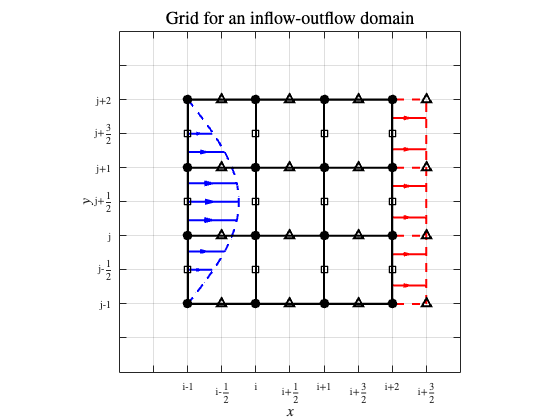

x = [-0.75 -0.75 0.75 0.75 -0.75];
y = [-0.75 0.75 0.75 -0.75 -0.75];
x2 = [-0.75 0.75];
y2 = [-0.75 1.];

figure
hold on; grid on; box on;
% set(gca,'fontsize',tickersize);
axis square
plot(x, y, 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
plot(y2, [0.25 0.25], 'LineStyle', '--', 'LineWidth', width, "Color", 'r');
plot(y2, [-0.25 -0.25], 'LineStyle', '--', 'LineWidth', width, "Color", 'r');
plot(y2, [-0.75 -0.75], 'LineStyle', '--', 'LineWidth', width, "Color", 'r');
plot(y2, [0.75, 0.75], 'LineStyle', '--', 'LineWidth', width, "Color", 'r');
plot([1., 1.], x2, 'LineStyle', '--', 'LineWidth', width, "Color", 'r');
plot([-0.75 -0.75], x2, 'LineStyle', '--', 'LineWidth', width, "Color", 'r');

plot(0.375 * sin(linspace(0, pi, 20)) - 0.75, linspace(-0.75, 0.75, 20), 'LineStyle', '--', 'LineWidth', width, "Color", 'b');
plot_arrow(-0.75, 0., -0.375, 0., 'b', 1.);
plot_arrow(-0.75, 0.5, -0.57, 0.5, 'b', 5.);
plot_arrow(-0.75, 0.135, -0.39, 0.135, 'b', 1.);
plot_arrow(-0.75, 0.365, -0.48, 0.365, 'b', 2.);
plot_arrow(-0.75, -0.135, -0.39, -0.135, 'b', 1.);
plot_arrow(-0.75, -0.5, -0.57, -0.5, 'b', 5.);
plot_arrow(-0.75, -0.365, -0.48, -0.365, 'b', 2.);

plot_arrow(0.75, 0.615, 1., 0.615, 'r', 2.);
plot_arrow(0.75, 0.385, 1., 0.385, 'r', 2.);
plot_arrow(0.75, 0.115, 1., 0.115, 'r', 2.);
plot_arrow(0.75, -0.115, 1., -0.115, 'r', 2.);
plot_arrow(0.75, -0.385, 1., -0.385, 'r', 2.);
plot_arrow(0.75, -0.615, 1., -0.615, 'r', 2.);

plot(x2, [0.25 0.25], 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot([0.25 0.25], x2, 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot(x2, [-0.25 -0.25], 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot([-0.25 -0.25], x2, 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot([-0.75 -0.75], x2, 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot([0.75, 0.75], x2, 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot(x2, [-0.75 -0.75], 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot(x2, [0.75, 0.75], 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);

plot(linspace(-0.75, 0.75, 4), -0.25 * ones(length(4), 1), 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);
plot(linspace(-0.75, 0.75, 4), 0.25 * ones(length(4), 1), 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);
plot(linspace(-0.75, 0.75, 4), 0.75 * ones(length(4), 1), 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);
plot(linspace(-0.75, 0.75, 4), -0.75 * ones(length(4), 1), 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);

plot(linspace(-0.75, 0.75, 4), -0.5 * ones(length(6), 1), 's', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);
plot(linspace(-0.75, 0.75, 4), zeros(length(6), 1), 's', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);
plot(linspace(-0.75, 0.75, 4), 0.5 * ones(length(6), 1), 's', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);

plot(linspace(-0.5, 1., 4), -0.75 * ones(length(4), 1), '^', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);
plot(linspace(-0.5, 1., 4), -0.25 * ones(length(4), 1), '^', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);
plot(linspace(-0.5, 1., 4), 0.25 * ones(length(4), 1), '^', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);
plot(linspace(-0.5, 1., 4), 0.75 * ones(length(4), 1), '^', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);

title('Grid for an inflow-outflow domain', 'FontSize', tsize + 4, 'Interpreter', "latex");
xlim([-1.25 1.25]); ylim([-1.25 1.25]);
ylabel('$y$', 'FontSize', lsize + 2), xlabel('$x$', 'FontSize', lsize + 2);
yticks(linspace(-1.25, 1.25, 11)); xticks(linspace(-1.25, 1.25, 11));
yticklabel = {" " " " "j-1" "j-$\frac{1}{2}$" "j" "j+$\frac{1}{2}$" "j+1" "j+$\frac{3}{2}$" "j+2" " " "" };
xticklabel = {" " " " "i-1" "i-$\frac{1}{2}$" "i" "i+$\frac{1}{2}$" "i+1" "i+$\frac{3}{2}$" "i+2" "i+$\frac{3}{2}$" " "};
set(gca, 'XTickLabels', xticklabel, 'TickLabelInterpreter', "latex");
set(gca, 'YTickLabels', yticklabel, 'TickLabelInterpreter', "latex");
xtickangle(0)
hold off

ax = gca;
ax.XAxis.FontSize = tickersize - 5;
ax.YAxis.FontSize = tickersize - 5;
ax.XLabel.FontSize = tickersize;
ax.YLabel.FontSize = tickersize;

## Space-time cells in 2D

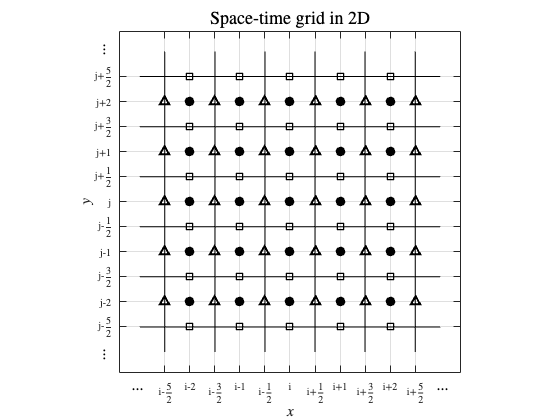

x2 = [-1.5 1.5];

figure
hold on; grid on; box on;
% set(gca,'fontsize',tickersize);
axis square
% plot(x, y, 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
plot([-1.25 -1.25], x2, 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
plot([1.25 1.25], x2, 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
plot(x2, [-1.25 -1.25], 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
plot(x2, [1.25 1.25], 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);

plot(x2, [0.25 0.25], 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
plot([0.25 0.25], x2, 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
plot(x2, [-0.25 -0.25], 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
plot([-0.25 -0.25], x2, 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
plot([-0.75 -0.75], x2, 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
plot([0.75, 0.75], x2, 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
plot(x2, [-0.75 -0.75], 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
plot(x2, [0.75, 0.75], 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);

plot(linspace(-1, 1, 5), -0.5 * ones(length(5), 1), 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);
plot(linspace(-1, 1, 5), 0.5 * ones(length(5), 1), 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);
plot(linspace(-1, 1, 5), -1 * ones(length(5), 1), 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);
plot(linspace(-1, 1, 5), zeros(length(5), 1), 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);
plot(linspace(-1, 1, 5), ones(length(5), 1), 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);
plot(linspace(-1.25, 1.25, 6), -1 * ones(length(6), 1), '^', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);
plot(linspace(-1.25, 1.25, 6), -0.5 * ones(length(6), 1), '^', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);
plot(linspace(-1.25, 1.25, 6), zeros(length(6), 1), '^', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);
plot(linspace(-1.25, 1.25, 6), 0.5 * ones(length(6), 1), '^', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);
plot(linspace(-1.25, 1.25, 6), ones(length(6), 1), '^', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);
plot(linspace(-1., 1., 5), -1.25 * ones(length(5), 1), 's', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);
plot(linspace(-1., 1., 5), -0.75 * ones(length(5), 1), 's', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);
plot(linspace(-1., 1., 5), -0.25 * ones(length(5), 1), 's', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);
plot(linspace(-1., 1., 5), 0.25 * ones(length(5), 1), 's', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);
plot(linspace(-1., 1., 5), 0.75 * ones(length(5), 1), 's', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);
plot(linspace(-1., 1., 5), 1.25 * ones(length(5), 1), 's', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);
text(-1.6, -1.825, '...', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(1.45, -1.825, '...', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(-1.9, -1.6, '...', 'FontSize', lsize + 3, 'Interpreter', "latex", 'rotation', 90);
text(-1.9, 1.45, '...', 'FontSize', lsize + 3, 'Interpreter', "latex", 'rotation', 90);

title('Space-time grid in 2D', 'FontSize', tsize + 4, 'Interpreter', "latex");
xlim([-1.7 1.7]); ylim([-1.7 1.7]);
ylabel('$y$', 'FontSize', lsize + 2), xlabel('$x$', 'FontSize', lsize + 2);
yticks(linspace(-1.25, 1.25, 11)); xticks(linspace(-1.25, 1.25, 11));
yticklabel = {"j-$\frac{5}{2}$" "j-2" "j-$\frac{3}{2}$" "j-1" "j-$\frac{1}{2}$" "j" "j+$\frac{1}{2}$" "j+1" "j+$\frac{3}{2}$" "j+2" "j+$\frac{5}{2}$"};
xticklabel = {"i-$\frac{5}{2}$" "i-2" "i-$\frac{3}{2}$" "i-1" "i-$\frac{1}{2}$" "i" "i+$\frac{1}{2}$" "i+1" "i+$\frac{3}{2}$" "i+2" "i+$\frac{5}{2}$"};
set(gca, 'XTickLabels', xticklabel, 'TickLabelInterpreter', "latex");
set(gca, 'YTickLabels', yticklabel, 'TickLabelInterpreter', "latex");
xtickangle(0)
hold off

ax = gca;
ax.XAxis.FontSize = tickersize - 5;
ax.YAxis.FontSize = tickersize - 5;
ax.XLabel.FontSize = tickersize;
ax.YLabel.FontSize = tickersize;

## Double periodic domain

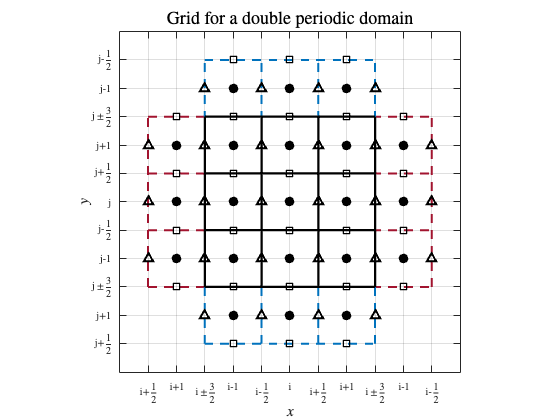

x = [-0.75 -0.75 0.75 0.75 -0.75];
y = [-0.75 0.75 0.75 -0.75 -0.75];
x2 = [-0.75 0.75];
y2 = [-1.25 1.25];

figure
hold on; grid on; box on;
% set(gca,'fontsize',tickersize);
axis square
plot(x, y, 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
% plot([-1.25 -1.25], x2, 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
% plot([1.25 1.25], x2, 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
% plot(x2, [-1.25 -1.25], 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
% plot(x2, [1.25 1.25], 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);

plot(y2, [0.25 0.25], 'LineStyle', '--', 'LineWidth', width, "Color", red);
plot(y2, [-0.25 -0.25], 'LineStyle', '--', 'LineWidth', width, "Color", red);
plot(y2, [-0.75 -0.75], 'LineStyle', '--', 'LineWidth', width, "Color", red);
plot(y2, [0.75, 0.75], 'LineStyle', '--', 'LineWidth', width, "Color", red);
plot(x2, [-1.25 -1.25], 'LineStyle', '--', 'LineWidth', width, "Color", blue);
plot(x2, [1.25, 1.25], 'LineStyle', '--', 'LineWidth', width, "Color", blue);

plot([-0.25 -0.25], y2, 'LineStyle', '--', 'LineWidth', width, "Color", blue);
plot([-0.75 -0.75], y2, 'LineStyle', '--', 'LineWidth', width, "Color", blue);
plot([0.75, 0.75], y2, 'LineStyle', '--', 'LineWidth', width, "Color", blue);
plot([0.25 0.25], y2, 'LineStyle', '--', 'LineWidth', width, "Color", blue);
plot([1.25, 1.25], x2, 'LineStyle', '--', 'LineWidth', width, "Color", red);
plot([-1.25 -1.25], x2, 'LineStyle', '--', 'LineWidth', width, "Color", red);

plot(x2, [0.25 0.25], 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot([0.25 0.25], x2, 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot(x2, [-0.25 -0.25], 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot([-0.25 -0.25], x2, 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot([-0.75 -0.75], x2, 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot([0.75, 0.75], x2, 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot(x2, [-0.75 -0.75], 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot(x2, [0.75, 0.75], 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);

plot(linspace(-1, 1, 5), -0.5 * ones(length(5), 1), 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);
plot(linspace(-1, 1, 5), 0.5 * ones(length(5), 1), 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);
plot(linspace(-0.5, 0.5, 3), -1 * ones(length(3), 1), 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);
plot(linspace(-1, 1, 5), zeros(length(5), 1), 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);
plot(linspace(-0.5, 0.5, 3), ones(length(3), 1), 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);

plot(linspace(-0.75, 0.75, 4), -1 * ones(length(4), 1), '^', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);
plot(linspace(-1.25, 1.25, 6), -0.5 * ones(length(6), 1), '^', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);
plot(linspace(-1.25, 1.25, 6), zeros(length(6), 1), '^', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);
plot(linspace(-1.25, 1.25, 6), 0.5 * ones(length(6), 1), '^', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);
plot(linspace(-0.75, 0.75, 4), ones(length(4), 1), '^', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);

plot(linspace(-0.5, 0.5, 3), -1.25 * ones(length(3), 1), 's', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);
plot(linspace(-1., 1., 5), -0.75 * ones(length(5), 1), 's', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);
plot(linspace(-1., 1., 5), -0.25 * ones(length(5), 1), 's', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);
plot(linspace(-1., 1., 5), 0.25 * ones(length(5), 1), 's', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);
plot(linspace(-1., 1., 5), 0.75 * ones(length(5), 1), 's', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);
plot(linspace(-0.5, 0.5, 3), 1.25 * ones(length(3), 1), 's', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);

title('Grid for a double periodic domain', 'FontSize', tsize + 4, 'Interpreter', "latex");
xlim([-1.5 1.5]); ylim([-1.5 1.5]);
ylabel('$y$', 'FontSize', lsize + 2), xlabel('$x$', 'FontSize', lsize + 2);
yticks(linspace(-1.25, 1.25, 11)); xticks(linspace(-1.25, 1.25, 11));
yticklabel = {"j+$\frac{1}{2}$" "j+1" "j$\pm \frac{3}{2}$" "j-1" "j-$\frac{1}{2}$" "j" "j+$\frac{1}{2}$" "j+1" "j$\pm \frac{3}{2}$" "j-1" "j-$\frac{1}{2}$"};
xticklabel = {"i+$\frac{1}{2}$" "i+1" "i$\pm \frac{3}{2}$" "i-1" "i-$\frac{1}{2}$" "i" "i+$\frac{1}{2}$" "i+1" "i$\pm \frac{3}{2}$" "i-1" "i-$\frac{1}{2}$"};
set(gca, 'XTickLabels', xticklabel, 'TickLabelInterpreter', "latex");
set(gca, 'YTickLabels', yticklabel, 'TickLabelInterpreter', "latex");
xtickangle(0)
hold off

ax = gca;
ax.XAxis.FontSize = tickersize - 5;
ax.YAxis.FontSize = tickersize - 5;
ax.XLabel.FontSize = tickersize;
ax.YLabel.FontSize = tickersize;

## Single periodic domain

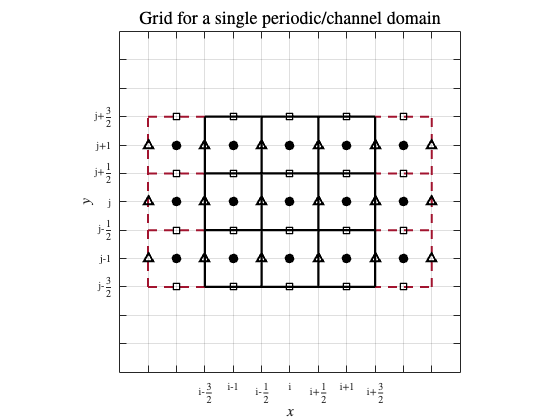

x = [-0.75 -0.75 0.75 0.75 -0.75];
y = [-0.75 0.75 0.75 -0.75 -0.75];
x2 = [-0.75 0.75];
y2 = [-1.25 1.25];

figure
hold on; grid on; box on;
% set(gca,'fontsize',tickersize);
axis square
plot(x, y, 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
% plot([-1.25 -1.25], x2, 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
% plot([1.25 1.25], x2, 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
% plot(x2, [-1.25 -1.25], 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
% plot(x2, [1.25 1.25], 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);

plot(y2, [0.25 0.25], 'LineStyle', '--', 'LineWidth', width, "Color", red);
plot(y2, [-0.25 -0.25], 'LineStyle', '--', 'LineWidth', width, "Color", red);
plot(y2, [-0.75 -0.75], 'LineStyle', '--', 'LineWidth', width, "Color", red);
plot(y2, [0.75, 0.75], 'LineStyle', '--', 'LineWidth', width, "Color", red);
plot([1.25, 1.25], x2, 'LineStyle', '--', 'LineWidth', width, "Color", red);
plot([-1.25 -1.25], x2, 'LineStyle', '--', 'LineWidth', width, "Color", red);

plot(x2, [0.25 0.25], 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot([0.25 0.25], x2, 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot(x2, [-0.25 -0.25], 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot([-0.25 -0.25], x2, 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot([-0.75 -0.75], x2, 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot([0.75, 0.75], x2, 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot(x2, [-0.75 -0.75], 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);
plot(x2, [0.75, 0.75], 'LineStyle', '-', 'LineWidth', width + 0.1, "Color", black);

plot(linspace(-1, 1, 5), -0.5 * ones(length(5), 1), 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);
plot(linspace(-1, 1, 5), 0.5 * ones(length(5), 1), 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);
plot(linspace(-1, 1, 5), zeros(length(5), 1), 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);

plot(linspace(-1.25, 1.25, 6), -0.5 * ones(length(6), 1), '^', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);
plot(linspace(-1.25, 1.25, 6), zeros(length(6), 1), '^', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);
plot(linspace(-1.25, 1.25, 6), 0.5 * ones(length(6), 1), '^', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);

plot(linspace(-1., 1., 5), -0.75 * ones(length(5), 1), 's', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);
plot(linspace(-1., 1., 5), -0.25 * ones(length(5), 1), 's', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);
plot(linspace(-1., 1., 5), 0.25 * ones(length(5), 1), 's', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);
plot(linspace(-1., 1., 5), 0.75 * ones(length(5), 1), 's', 'MarkerSize', msize - 2, 'LineWidth', width, 'Color', black);

title('Grid for a single periodic/channel domain', 'FontSize', tsize + 4, 'Interpreter', "latex");
xlim([-1.5 1.5]); ylim([-1.5 1.5]);
ylabel('$y$', 'FontSize', lsize + 2), xlabel('$x$', 'FontSize', lsize + 2);
yticks(linspace(-1.25, 1.25, 11)); xticks(linspace(-1.25, 1.25, 11));
yticklabel = {" " " " "j-$\frac{3}{2}$" "j-1" "j-$\frac{1}{2}$" "j" "j+$\frac{1}{2}$" "j+1" "j+$\frac{3}{2}$" " " " "};
xticklabel = {" " " " "i-$\frac{3}{2}$" "i-1" "i-$\frac{1}{2}$" "i" "i+$\frac{1}{2}$" "i+1" "i+$\frac{3}{2}$" " " " "};
set(gca, 'XTickLabels', xticklabel, 'TickLabelInterpreter', "latex");
set(gca, 'YTickLabels', yticklabel, 'TickLabelInterpreter', "latex");
xtickangle(0)
hold off

ax = gca;
ax.XAxis.FontSize = tickersize - 5;
ax.YAxis.FontSize = tickersize - 5;
ax.XLabel.FontSize = tickersize;
ax.YLabel.FontSize = tickersize;

## General grid

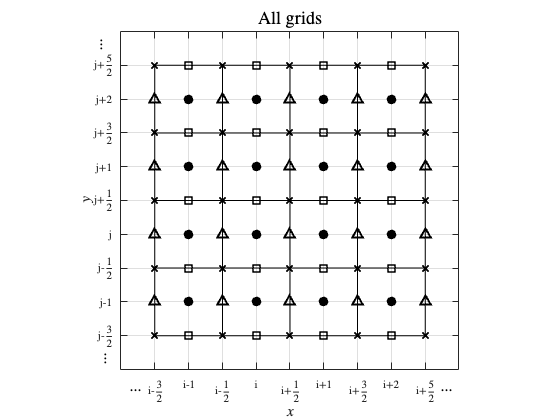

x = [-1 -1 1 1 -1];
y = [-1 1 1 -1 -1];
x2 = [-1 1];
y2 = [0 0];

figure
hold on; grid on; box on;
% set(gca,'fontsize',tickersize);
axis square
plot(x, y, 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
plot([-1 -1], x2, 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
plot([1 1], x2, 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
plot(x2, [-1 -1], 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
plot(x2, [1 1], 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);

plot(x2, y2, 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
plot(y2, x2, 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
plot([-0.5 -0.5], x2, 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
plot([0.5, 0.5], x2, 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
plot(x2, [-0.5 -0.5], 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
plot(x2, [0.5, 0.5], 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
plot(linspace(-1, 1, 5), -0.5 * ones(length(5), 1), 'x', 'MarkerSize', msize - 1, 'LineWidth', width, 'Color', black);
plot(linspace(-1, 1, 5), 0.5 * ones(length(5), 1), 'x', 'MarkerSize', msize - 1, 'LineWidth', width, 'Color', black);
plot(linspace(-1, 1, 5), -1 * ones(length(5), 1), 'x', 'MarkerSize', msize - 1, 'LineWidth', width, 'Color', black);
plot(linspace(-1, 1, 5), zeros(length(5), 1), 'x', 'MarkerSize', msize - 1, 'LineWidth', width, 'Color', black);
plot(linspace(-1, 1, 5), ones(length(5), 1), 'x', 'MarkerSize', msize - 1, 'LineWidth', width, 'Color', black);
plot(linspace(-0.75, 0.75, 4), -1 * ones(length(4), 1), 's', 'MarkerSize', msize - 1, 'LineWidth', width, 'Color', black);
plot(linspace(-0.75, 0.75, 4), -0.5 * ones(length(4), 1), 's', 'MarkerSize', msize - 1, 'LineWidth', width, 'Color', black);
plot(linspace(-0.75, 0.75, 4), zeros(length(4), 1), 's', 'MarkerSize', msize - 1, 'LineWidth', width, 'Color', black);
plot(linspace(-0.75, 0.75, 4), 0.5 * ones(length(4), 1), 's', 'MarkerSize', msize - 1, 'LineWidth', width, 'Color', black);
plot(linspace(-0.75, 0.75, 4), ones(length(4), 1), 's', 'MarkerSize', msize - 1, 'LineWidth', width, 'Color', black);
plot(linspace(-1., 1., 5), -0.75 * ones(length(5), 1), '^', 'MarkerSize', msize - 1, 'LineWidth', width, 'Color', black);
plot(linspace(-1., 1., 5), -0.25 * ones(length(5), 1), '^', 'MarkerSize', msize - 1, 'LineWidth', width, 'Color', black);
plot(linspace(-1., 1., 5), 0.25 * ones(length(5), 1), '^', 'MarkerSize', msize - 1, 'LineWidth', width, 'Color', black);
plot(linspace(-1., 1., 5), 0.75 * ones(length(5), 1), '^', 'MarkerSize', msize - 1, 'LineWidth', width, 'Color', black);

plot(linspace(-0.75, 0.75, 4), -0.75 * ones(length(4), 1), 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);
plot(linspace(-0.75, 0.75, 4), -0.25 * ones(length(4), 1), 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);
plot(linspace(-0.75, 0.75, 4), 0.25 * ones(length(4), 1), 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);
plot(linspace(-0.75, 0.75, 4), 0.75 * ones(length(4), 1), 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black, 'Color', black);

text(-1.2, -1.375, '...', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(1.1, -1.375, '...', 'FontSize', lsize + 3, 'Interpreter', "latex");
text(-1.4, -1.225, '...', 'FontSize', lsize + 3, 'Interpreter', "latex", 'rotation', 90);
text(-1.425, 1.1, '...', 'FontSize', lsize + 3, 'Interpreter', "latex", 'rotation', 90);

title('All grids', 'FontSize', tsize + 4, 'Interpreter', "latex");
xlim([-1.25 1.25]); ylim([-1.25 1.25]);
ylabel('$y$', 'FontSize', lsize + 2), xlabel('$x$', 'FontSize', lsize + 2);
yticks(linspace(-1., 1., 9)); xticks(linspace(-1., 1., 9));
yticklabel = {"j-$\frac{3}{2}$" "j-1" "j-$\frac{1}{2}$" "j" "j+$\frac{1}{2}$" "j+1" "j+$\frac{3}{2}$" "j+2" "j+$\frac{5}{2}$"};
xticklabel = {"i-$\frac{3}{2}$" "i-1" "i-$\frac{1}{2}$" "i" "i+$\frac{1}{2}$" "i+1" "i+$\frac{3}{2}$" "i+2" "i+$\frac{5}{2}$"};
set(gca, 'XTickLabels', xticklabel, 'TickLabelInterpreter', "latex");
set(gca, 'YTickLabels', yticklabel, 'TickLabelInterpreter', "latex");
xtickangle(0)
hold off

ax = gca;
ax.XAxis.FontSize = tickersize - 4;
ax.YAxis.FontSize = tickersize - 4;
ax.XLabel.FontSize = tickersize;
ax.YLabel.FontSize = tickersize;

## Arrow function

function plot_arrow(x_start, y_start, x_end, y_end, colour, asize)

% Calculate the midpoint coordinates
% x_mid = (x_start + x_end) / 2;
% y_mid = (y_start + y_end) / 2;

% Calculate the half-length vector for the arrow
dx = (x_end - x_start) / 2;
dy = (y_end - y_start) / 2;

plot([x_start, x_end], [y_start, y_end], colour, 'LineWidth', 2); % Optional: plot the full line
quiver(x_start, y_start, dx, dy, 0, 'Color', colour, 'LineWidth', 2, 'MaxHeadSize', asize);
% axis equal; % Optional, for equal scaling on both axes

end

## FD cell

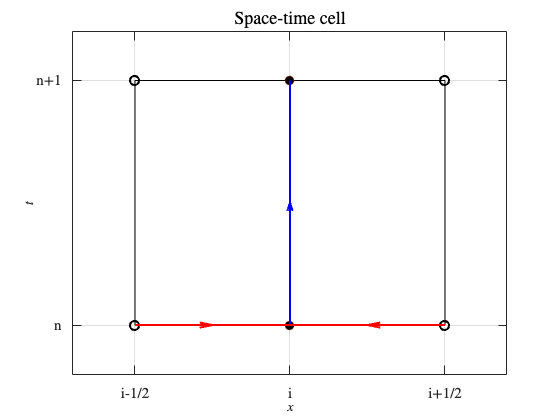

x = [-1 -1 0 0 -1];
y = [0 1 1 0 0];
x2 = [-1 1];
y2 = [0 0];

% x_start = -0.5; % x-coordinate of starting point
% y_start = 0; % y-coordinate of starting point
% x_end = 0;   % x-coordinate of end point
% y_end = 1;   % y-coordinate of end point

figure
hold on; grid on; box on;
set(gca,'fontsize',tickersize)
plot(x, y, 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
% plot(x2, y2, 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
% plot(y2, x2, 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
% plot(x2, x2, 'LineStyle', '--', 'LineWidth', width - 1, "Color", black);
% plot(-x2, x2, 'LineStyle', '--', 'LineWidth', width - 1, "Color", black);
% plot([0 -1 0 1 0], [1 0 -1 0 1], 'LineStyle', '--', 'LineWidth', width - 1, "Color", black);
plot([-0.5 -0.5], [0 1], 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black);
plot([-1 0 -1 0], [0 0 1 1], 'o', 'MarkerSize', msize - 1, 'LineWidth', width, 'Color', black);
plot_arrow(-1, 0, -0.5, 0, 'r', 0.5);
plot_arrow(-0.5, 0, -0.5, 1, 'b', 0.2);
plot_arrow(0, 0, -0.5, 0, 'r', 0.5);
title('Space-time cell', 'FontSize', tsize + 4, 'Interpreter', "latex");
% text(-0.15, 1.115, '$\xi_2$', 'FontSize', lsize + 3, 'Interpreter', "latex")
% text(1.07, -0.125, '$\xi_1$', 'FontSize', lsize + 3, 'Interpreter', "latex")
% text(-0.15, -0.1, '$(0, 0)$', 'FontSize', lsize + 3.5, 'Interpreter', "latex")
xlim([-1.2 0.2]); ylim([-0.2 1.2]);
ylabel('$t$', 'FontSize', lsize + 2), xlabel('$x$', 'FontSize', lsize + 2);
yticks([0 1]); xticks([-1 -0.5 0]);
yticklabel = {"n" "n+1"};
xticklabel = {"i-1/2" "i" "i+1/2"};
set(gca, 'XTickLabels', xticklabel, 'TickLabelInterpreter', "latex")
set(gca, 'YTickLabels', yticklabel, 'TickLabelInterpreter', "latex")
hold off


ax = gca;
% exportgraphics(ax,'/Users/wayne/Desktop/NumericsCDT/report/pres_figs/fdstcell.eps','Resolution',300)

## CABARET cell

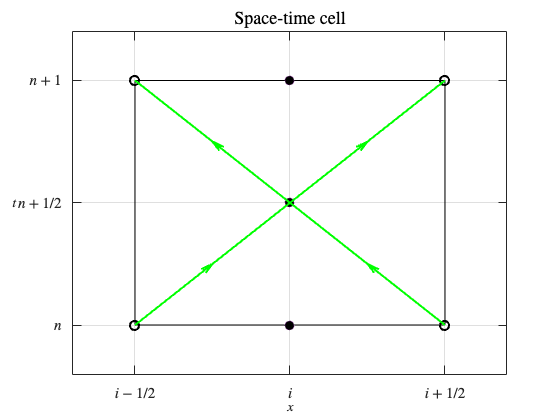

x = [-1 -1 0 0 -1];
y = [0 1 1 0 0];

figure
hold on; grid on; box on;
set(gca,'fontsize',tickersize)
plot(x, y, 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
plot([0 -1], [0 1], 'LineStyle', '--', 'LineWidth', width - 1, "Color", black);
plot([-1 0], [0 1], 'LineStyle', '--', 'LineWidth', width - 1, "Color", black);
plot([-0.5 -0.5 -0.5], [0 0.5 1], 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black);
plot([-1 0 -1 0], [0 0 1 1], 'o', 'MarkerSize', msize - 1, 'LineWidth', width, 'Color', black);
% plot_arrow(-1, 1, -0.5, 1, 'r', 0.5);
% plot_arrow(-0.5, 0.5, -0.5, 1, 'b', 0.5);
% plot_arrow(0, 1, -0.5, 1, 'r', 0.5);
plot_arrow(-1, 0, -0.5, 0.5, 'g', 0.5);
plot_arrow(0, 0, -0.5, 0.5, 'g', 0.5);
plot_arrow(-0.5, 0.5, -1, 1, 'g', 0.5);
plot_arrow(-0.5, 0.5, 0, 1, 'g', 0.5);
title('Space-time cell', 'FontSize', tsize + 4, 'Interpreter', "latex");
xlim([-1.2 0.2]); ylim([-0.2 1.2]);
ylabel('$t$', 'FontSize', lsize + 2, Rotation=0), xlabel('$x$', 'FontSize', lsize + 2);
yticks([0 0.5 1]); xticks([-1 -0.5 0]);
yticklabel = {"$n$" "$n+1/2$" "$n+1$"};
xticklabel = {"$i-1/2$" "$i$" "$i+1/2$"};
set(gca, 'XTickLabels', xticklabel, 'TickLabelInterpreter', "latex")
set(gca, 'YTickLabels', yticklabel, 'TickLabelInterpreter', "latex")
hold off


ax = gca;
% exportgraphics(ax,'/Users/wayne/Desktop/Papers/ESA/pres_figs/cabextrapz.eps','Resolution',300)

## NCP

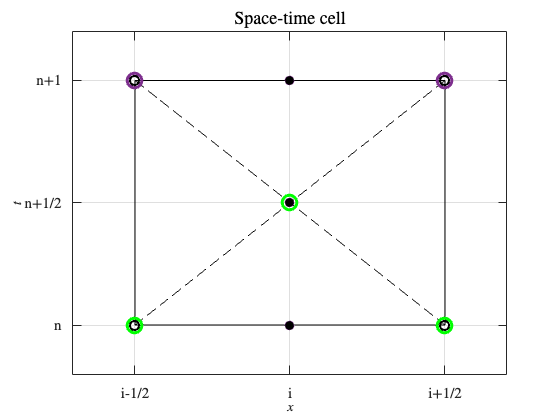

x = [-1 -1 0 0 -1];
y = [0 1 1 0 0];

figure
hold on; grid on; box on;
set(gca,'fontsize',tickersize)
plot(x, y, 'LineStyle', '-', 'LineWidth', width - 1, "Color", black);
plot([0 -1], [0 1], 'LineStyle', '--', 'LineWidth', width - 1, "Color", black);
plot([-1 0], [0 1], 'LineStyle', '--', 'LineWidth', width - 1, "Color", black);
plot([-0.5 -0.5 -0.5], [0 0.5 1], 'o', 'MarkerSize', msize - 1, 'MarkerFaceColor', black);
plot([-1 0 -1 0], [0 0 1 1], 'o', 'MarkerSize', msize - 1, 'LineWidth', width, 'Color', black);
plot([-1 -0.5 0], [0 0.5 0], 'o', 'MarkerSize', msize + 4.5, 'LineWidth', width + 1, 'Color', 'g');
plot([-1 0], [1 1], 'o', 'MarkerSize', msize + 4.5, 'LineWidth', width + 1, 'Color', purple);
title('Space-time cell', 'FontSize', tsize + 4, 'Interpreter', "latex");
xlim([-1.2 0.2]); ylim([-0.2 1.2]);
ylabel('$t$', 'FontSize', lsize + 2), xlabel('$x$', 'FontSize', lsize + 2);
yticks([0 0.5 1]); xticks([-1 -0.5 0]);
yticklabel = {"n" "n+1/2" "n+1"};
xticklabel = {"i-1/2" "i" "i+1/2"};
set(gca, 'XTickLabels', xticklabel, 'TickLabelInterpreter', "latex")
set(gca, 'YTickLabels', yticklabel, 'TickLabelInterpreter', "latex")
hold off


ax = gca;
% exportgraphics(ax,'/Users/wayne/Desktop/NumericsCDT/report/pres_figs/cabncp.eps','Resolution',300)

## Interface convention

% figure
% hold on; grid off; box off
% set(gca,'visible','off')
% plot(0.25, 0, '|', 'LineWidth', width, 'MarkerSize', msize + 5, 'Color', black)
% plot(0.75, 0, '|', 'LineWidth', width, 'MarkerSize', msize + 5, 'Color', black)
% text(0.5, -0.01, '$\Omega^c$', 'FontSize', lsize + 3.5, 'Interpreter', "latex")
% text(0.26, 0.01, '$-$', 'FontSize', lsize + 3.5, 'Interpreter', "latex")
% text(0.7, 0.01, '$-$', 'FontSize', lsize + 3.5, 'Interpreter', "latex")
% text(0.19, 0.01, '$+$', 'FontSize', lsize + 3.5, 'Interpreter', "latex")
% text(0.77, 0.01, '$+$', 'FontSize', lsize + 3.5, 'Interpreter', "latex")
% plot([0.05 0.95], [0 0], 'color', black, 'LineWidth', width - 1)
% xlim([-0.1 1.1]), ylim([-0.1 0.1]);
% hold off
% 
% ax = gca;
% exportgraphics(ax,'/Users/jwtan/Desktop/dgProject/Plots/interface_conv.eps','Resolution',300)

## One interface

% figure
% hold on; grid off; box off
% set(gca,'visible','off')
% plot(0.5, 0, '|', 'LineWidth', width, 'MarkerSize', msize + 5, 'Color', black)
% text(0.35, -0.01, '$\Omega^c$', 'FontSize', lsize + 3.5, 'Interpreter', "latex")
% text(0.55, -0.01, '$\Omega^{c+1}$', 'FontSize', lsize + 3.5, 'Interpreter', "latex")
% text(0.44, 0.01, '$-$', 'FontSize', lsize + 3.5, 'Interpreter', "latex")
% text(0.51, 0.01, '$+$', 'FontSize', lsize + 3.5, 'Interpreter', "latex")
% plot([0.25 0.75], [0 0], 'color', black, 'LineWidth', width - 1)
% xlim([-0.1 1.1]), ylim([-0.1 0.1]);
% hold off
% 
% ax = gca;
% exportgraphics(ax,'/Users/jwtan/Desktop/dgProject/Plots/one_interface.eps','Resolution',300)

## Functions

function pvec(x,y,r,fi,color,style,linewidth,endposition)
%% Plotting vectors in polar coordinate system
%  Author: Matevž Lavtar
%% Setting space
x0= 0;                           % x origin of system 
y0= 0;                            % y origin of system
alpha = deg2rad(fi);             % angle fi from degree to radian
k1=0.05;                         % factor of lenght of arro
k2 = 0.01;                       % factor of width of arrow
theta1 = 20;                     % angle of arrow relative to vector line in degree
theta = theta1*(pi/180);
R = [cos(alpha) -sin(alpha) 0 x0;...  % rotation around z axis
    sin(alpha) cos(alpha) 0 y0;...
    0 0 0 0;...
    0 0 0 1];
% origin vector
p0 = [x0; y0; 0;1];
% start positon of vector
p1 = [x0+r; y0; 0;1];
% arrow
pA = [(x+r)-k1*(r+x); k2*(r+x); 0;1];
pB = [(x+r)-k1*(r+x); -k2*(r+x); 0;1];
p2 = R*p1;
pA2 = R*pA;
pB2 = R*pB;
xA = pA2(1);
yA = pA2(2);
xB = pB2(1);
yB = pB2(2);
xC = p2(1);
yC = p2(2);
if x ~= 0
    yC=r;
    yA= yC-0.05*r;
    yB= yC-0.05*r;
end
%% Default parameters settings
 if ~exist('color','var')
    color = "blue";
 end
  if ~exist('style','var')
    style = "-";
  end
  if ~exist('linewidth','var')
    linewidth = 1;
  end
   if ~exist('endposition','var')
    endposition = 0;
 end
%% Plot vector with arrow
plot([x0+x;xC+x],[y0+y;yC+y],"Color",color,"LineStyle",style,"LineWidth",linewidth)
% hold on
plot([xC+x;xA+x],[yC+y; yA+y],[xC+x;xB+x],[yC+y; yB+y],"Color",color,"LineStyle",'-',"LineWidth",linewidth,'HandleVisibility','off')
daspect([1 1 1])
% grid on
% hold off
if endposition == 1
    xc = xC+x
    yc = yC+y
end
end